## 神经网络案例

山东理工大学 数学院  周世祥 shixiangbupt@qq.com

人工神经网络---模拟人脑的思考方式

神经网络是由一系列层次化的，对变量线性组合后又执行非线性变换的函数构建的数学模型，能对任意复杂的数学模型进行精度非常高的逼近。

通过神经网络，能够模拟诸多复杂的人脑活动，如图像识别，模式识别，语言理解，空间感知等。

神经网络结构是对人脑神经元结构的一种简单模仿，网络中的节点相当于人脑中的神经元，连接节点的权重相当于神经元之间突触的连接强度。

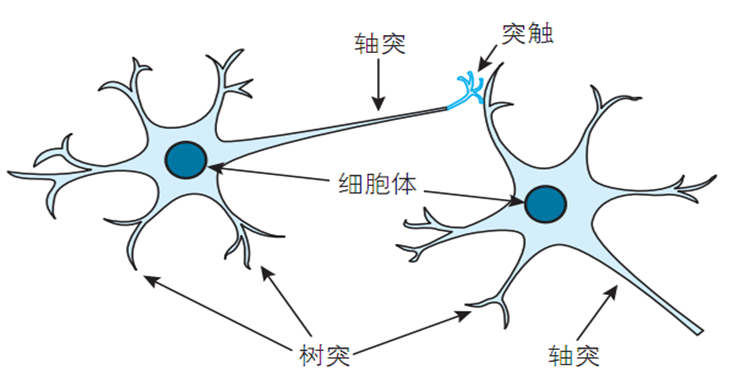

     1943年，心理学家McCulloch与数学家Pitts两人给出了一个理想的神经元模型，简称MP模型。 

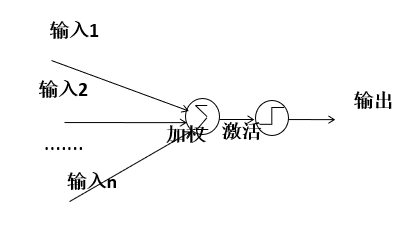

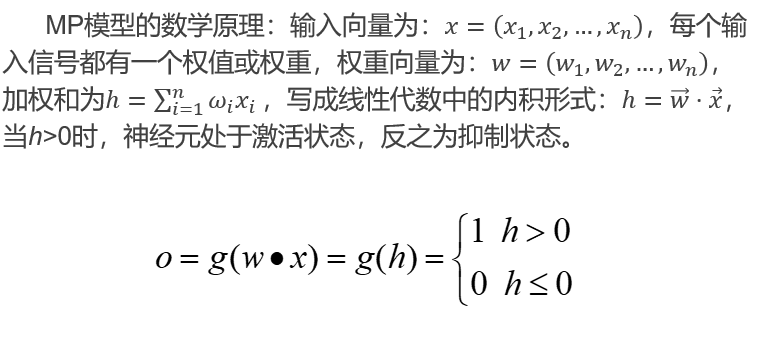

一个简单的应用案例：班级同学的年底评优方案。

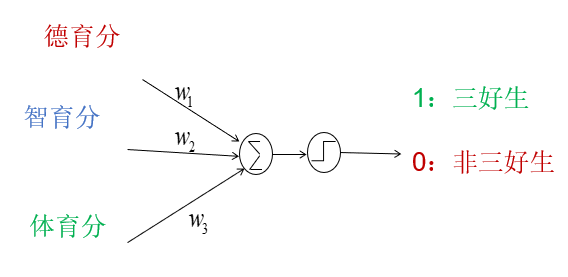

本质上是一个分类器，分类界面为超平面。

1957年由康奈尔大学的罗森布拉特提出了单层感知机模型，称为神经网络中的“Hello World”。仅有输入层和输出层构成，网络的输入和输出数量是由外部问题所确定的。 

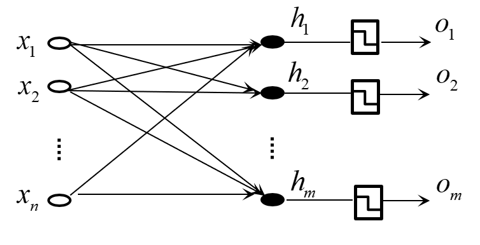

**感知机的学习规则**

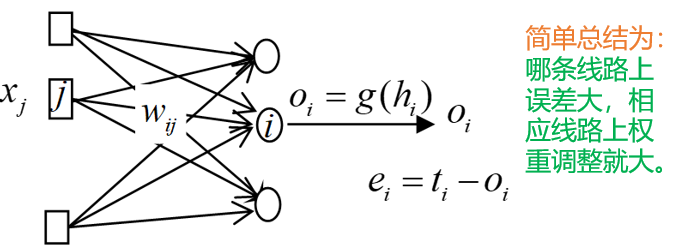

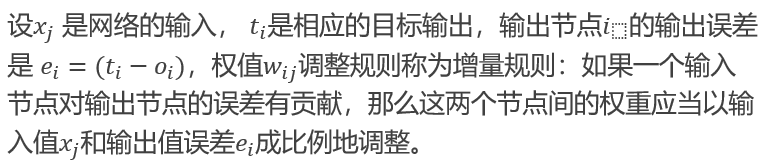

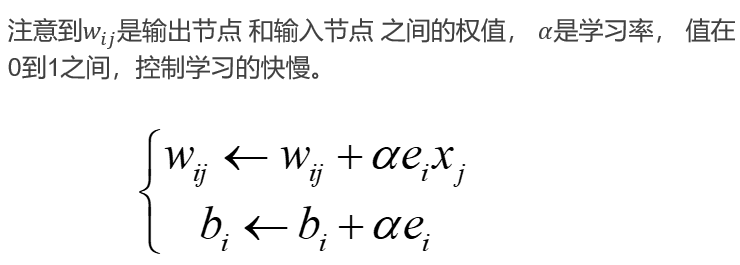

罗森布拉特证明了感知机收敛定理：给定一个线性可分的数据集，感知机将在有限次迭代之后收敛。只要最优权值存在，学习规则就一定会使网络收敛到该权值上。

多层前馈网络，简称MLP，以层为功能单位，同层神经元之间无连接，上层与下层实现全连接，无跨层连接。输入层只负责接收信号输入，无数据处理功能，隐藏层和输出层是由具有信号处理功能的神经元构成，下图显示了有一个隐藏层的多层神经网络结构。

**通用逼近定理 **：不需超过二层，具有足够多隐藏层节点的神经网络能以任意精度逼近任意连续函数。通用逼近定理表明了神经网络计算的普适性。

**网络参数：**各个神经元之间的连接权值，起初是随机的，只有通过不断训练学习才能求出来。

**网络超参数：**网络的层数，每层的节点数，激活函数，凭经验事先指定。

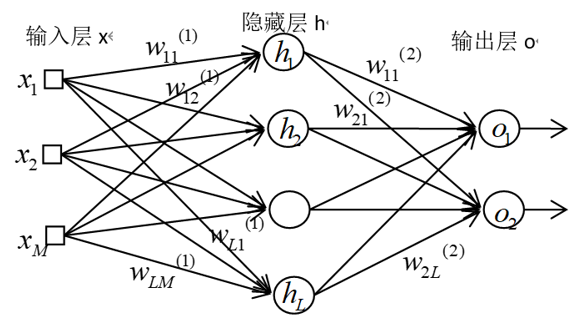

一般神经网络往往由输入层，多个隐藏层，以及输出层构成，浅层神经网络的输出作为深层神经网络的输入，每个隐藏层网络都对输入进行非线性变换，在输入层中，每个节点都对应于样本特征向量中的一个特征值，输出层中的节点则代表模型的计算结果。

**激活函数**：唯一的非线性部件，神经网络逼近能力的源泉。

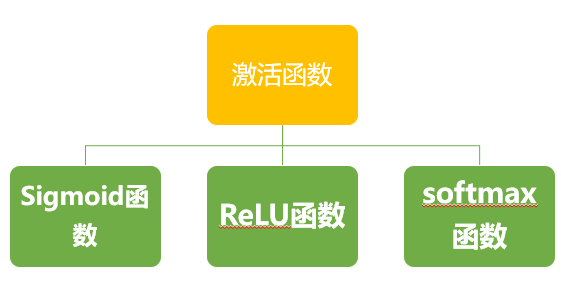

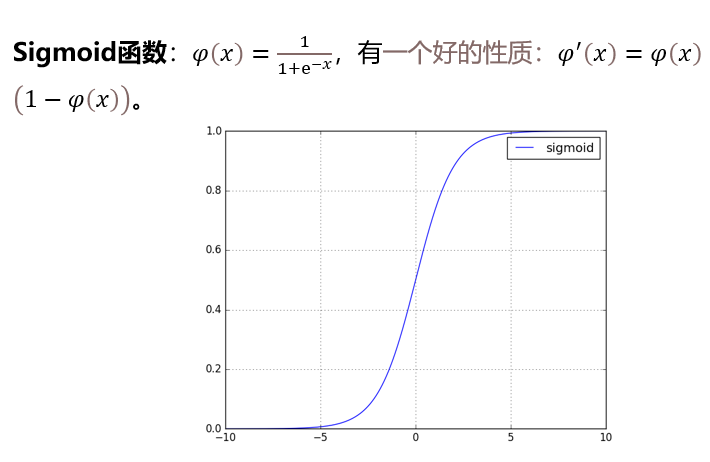

**softmax****函数：**又称归一化指数函数。它是二分类函数sigmoid在多分类上的推广，目的是将多分类的结果以概率的形式展现出来。

例如，当三个输出节点接收的加权和分别为2,1,0.1时，需要在分母上对所有输入求加权和，即

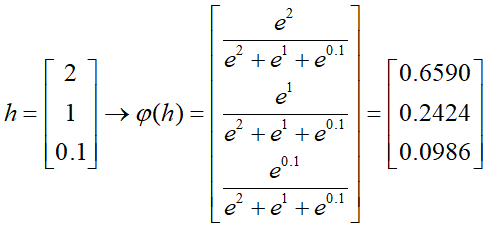

输出分三类，此时识别为第一类

**如何训练多层前馈网络：**前面介绍的增量规则对于多层网络的训练来说是不起作用的，因为对于输出神经元我们不知道输入，对于隐藏层我们不知道目标，对于额外的隐藏层，我们既不知道输入也不知道目标，我们没法考察节点计算误差。

1986年，反向传播算法，也称BP算法，最终解决了多层神经网络的训练问题。意义在于提供了一种确定隐藏层误差的系统方法，一旦确定好隐藏层误差，就可以使用增量规则去调整权重。

**1.****目标函数和学习规则：**训练值和真实值之间的差异就称为损失函数或代价函数，优化理论中称为目标函数。

均方误差损失函数定义为：$\bar{J} =\frac{1}{2}\sum_{i=1}^M {\left(t_i -O_i \right)}^2$ 

O_i是输出节点的输出， t_i是来自训练数据的正确输出。

损失函数表示为所有参数(权值和偏置)的函数：

         
$$\bar{J} =\bar{J} \left(w,b\right)$$


训练的目的调整参数(w,b) ，使得$\bar{J}$不断缩小，逼近于0，注意到参数都是向量，这是一个典型的多元函数优化问题。

`在数值分析领域，梯度下降法也称为最速下降法。就像你从山顶下来，每次都沿着最陡坡度出发，最终能最快到达最低谷。`

`函数` `中，`$x$`当``改变`$\triangle x$`，`$y$`改变`$\triangle y$`时``，考察`$f\left(x,y\right)$`的值的变化。`

`可以写成两个向量的内积形式：`


$$\Delta z=\frac{\partial z}{\partial x}\Delta x+\frac{\partial z}{\partial y}\Delta y=\left(\frac{\partial z}{\partial x},\frac{\partial z}{\partial y}\right)\left(\Delta x,\Delta y\right)$$


`在解析几何中我们知道当两个向量方向相反时，内积取最小值。`

 `我们把式中的向量`$\nabla f=\left(\frac{\partial z}{\partial x},\frac{\partial z}{\partial y}\right)$`定义为函数的梯度换句话说：函数对各个自变量的偏导数组成的向量。`

`梯度是指向函数值上升最快的方向，而负梯度方向就是函数值下降最快的方向。梯度的范数越大，函数上升越快。`

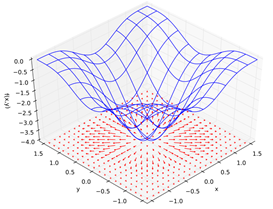

`函数`$f\left(x,y\right)=-{\left(\sin \;x^2 +\cos \;x^2 \right)}^2$`及其梯度可视化`

`只要沿着梯度方向的反方向改变自变量，函数的值就有希望变小,梯度在函数优化中有重要的意义.`

$\left(\Delta x,\Delta y\right)=-\alpha \nabla f\;$($\alpha$`为调整步长`) 

`神经网络的层数越多，其性能越差，原因是层数越多，训练越困难，反向传播算法面临着如下的难题：`

` 梯度消失，梯度可以认为与反向传播算法中的增量类似，当输出误差很可能无法到达更远的节点时，就会造成在使用反向传播算法的训练过程中出现梯度消失的现象。`

`将输出误差反向传播至隐藏层来训练神经网络，但当误差几乎无法到达第一个隐藏层时，权值就得不到调整，这样输入层附近的隐藏层就得不到恰当的训练，增加的隐藏层就变得毫无意义。``解决梯度消失问题的典型方法是将整流线型单元函数`(ReLU)`作为激活函数，它比`sigmoid`函数能更好地传递误差.`

**梯度下降法：**梯度是什么呢？

如何能找到损失函数如何能找到损失函数$\bar{J} \left(w,b\right)$的全局最小点？因为$\bar{J} \left(w,b\right)$是连续可微的，根据微积分常识，理论上导数为零的点是函数极小值点。多元函数的梯度概念，即为一元函数导数概念的推广，我们只要沿着负梯度方向按某一步长前进，总能找到函数的极小值.  

定义损失函数梯度：$\nabla \bar{J} =\left(\frac{\partial \bar{J} }{\partial w},\frac{\partial \bar{J} }{\partial b}\right)$

** 梯度下降法：**算法原理：

沿着梯度方向的反方向改变自变量，函数的值就有希望变小。梯度在函数优化中有重要的意义。

η也称为学习率，训练前指定。上述参数调整策略就是梯度下降法，只要沿着梯度方向的反方向改变自变量，函数的值就有希望变小。

反向传播算法一个通俗的解释：(为便于理解，去掉了激活函数)

通过反向传播算法回传误差改进链路权值，权值如何确定？

网络初建时，权值等于任何值都可以，一般随机把权值初始化为0~1之间。

链路权值决定了最终的输出，拿到输出后，会与正确的答案相比较，看输出结果与正确结果的偏差是否大，如果偏差太大，表明当前网络中链路权值的设置不合理，需要重新修改，问题在于如何修改这么多权值，使得最终输出结果与正确结果偏差越来越小。

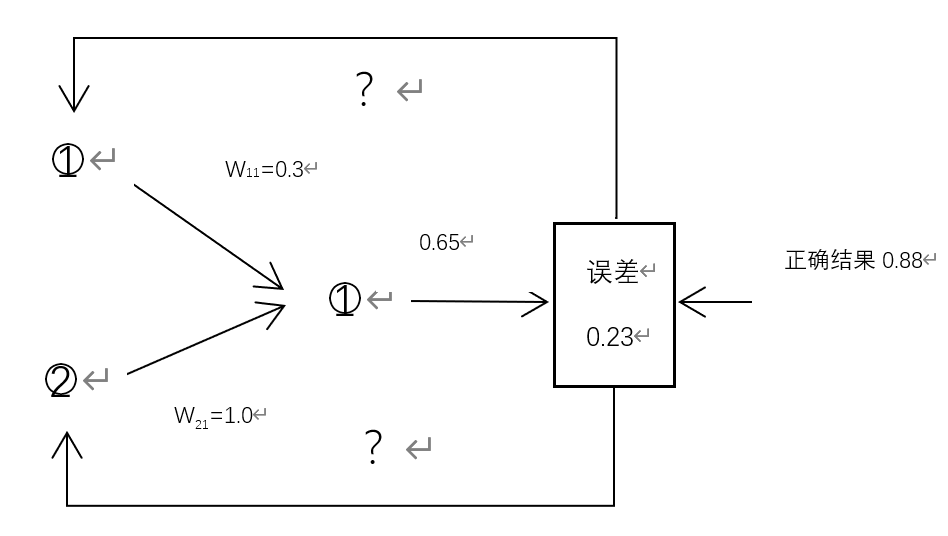

利用误差来改进参数$w_{11} ,w_{21}$

如何改进？

把神经网络误差看成一个多变量函数$F\left(w_{11} ,w_{12} ,\cdots \;\right)=f\left(w_{11} ,w_{12} ,\cdots \right)-y=y^{\prime } -y$

要想使得$y^{\prime } -y$值变小，即最小化目标函数，就是一个优化问题，这个问题因为变量太大，没有解析解，可以用迭代法求数值解。

例： $F\left(x,y\right)=\frac{x^2 +y^2 }{2}$的极值，回忆回忆高数上讲的极值存在充分条件

每改变一个权值，都会对最后的输出结果有影响，每个链路权值对最终的偏差都负有责任，问题在于这个责任如何分配，最终误差0.23，那么$w_{11}$应付多少责任，$w_{21}$又负多少责任？

正常的思路是谁的权值大，负责的机会就大。

$w_{11}$所占的比重为$\frac{w_{11} }{w_{11} +w_{21} }=\frac{0\ldotp 3}{1\ldotp 3}\;$

分配给$w_{11}$的误差为$0\ldotp 23*\frac{0\ldotp 3}{1\ldotp 3}=0\ldotp 053$

同理，参数$w_{21}$误差为$0\ldotp 23*\frac{1}{1\ldotp 3}=0\ldotp 177$

如果，网络不止一层，误差继续按比例回传。

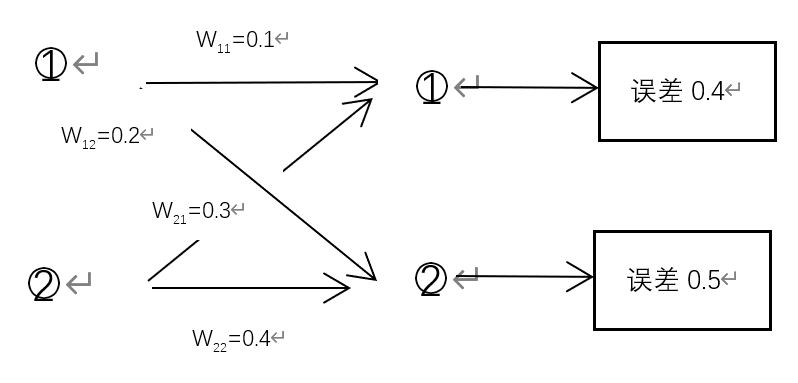

输出层节点1回传给最外层节点1误差：$0\ldotp 4*\frac{w_{11} }{w_{11} +w_{21} }=0\ldotp 4*\frac{0\ldotp 1}{0\ldotp 1+0\ldotp 3}=0\ldotp 1$

输出层节点2回传给最外层节点1误差：$0\ldotp 5*\frac{w_{12} }{w_{12} +w_{22} }=0\ldotp 5*\frac{0\ldotp 2}{0\ldotp 2+0\ldotp 4}=0\ldotp 15$

最左边网络层的1号神经元应该接收的误差为0.1+0.15=0.25

这种先从输出层获取误差，然后按链路参数权值比把误差反传回去的方式，就是神经网络回传机制。

使用矩阵表示和梯度下降法实现神经网络的迭代训练：

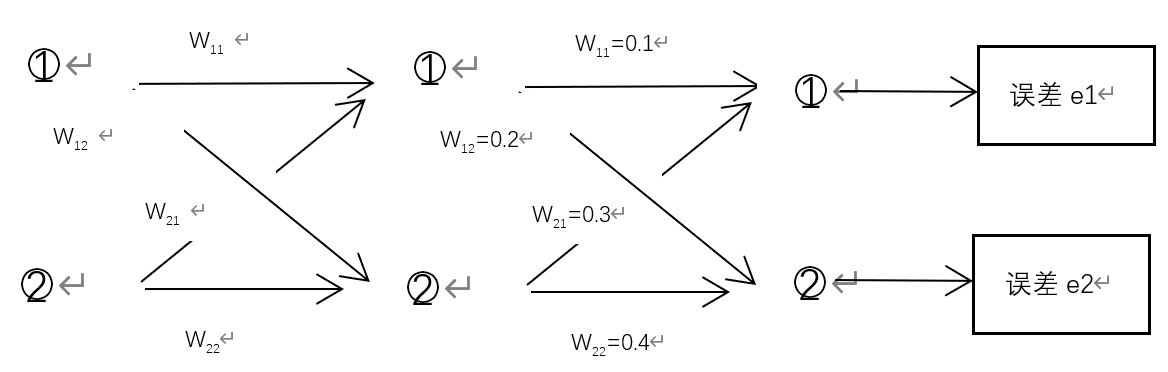

由于神经网络通常包含很多参数，而且涉及较多的非线性激活函数，故一般不便于求二阶导数(黑塞矩阵)，无法使用牛顿法，因此，常使用梯度下降法训练神经网络。

对于多层神经网络，越靠近网络右边(后端)的参数，其导数越容易计算，反向传播算法使用微积分“链式法则”将靠左边参数的导数递归地表示为靠右边的参数之导数的函数。

在训练网络之前，一般建议将全部特征变量归一化，或标准化，否则，特征变量取值范围大，会影响网络的权值参数。

**如何训练网络：**“轮”(epoch),轮数是全部训练数据都参与训练的循环次数。每学习完一遍数据集，就称为1个epoch。例如，数据集中有1000个样本，批大小为10，那么将全部样本训练1遍后，网络会被调整1000/10，即100次。

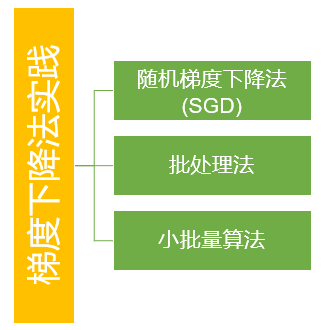

**多层神经网络学习规则：**在含有多个隐藏层的神经网络中，如何计算每层参数的梯度向量，进而调整参数，需要用到著名的误差反向传播算法。人们花费了30年的时间才为单层神经网络增加了一层，为什么这么难，就是因为没有找到适合多层神经网络的学习规则，1986年反向传播算法被提出来后，神经网络又回到历史舞台。

在网络前向传播时，可以看到损失函数是权重的复合函数，靠近输入层的权重，复合层次越深，所以在求梯度时，越靠近前面的层，根据复合函数求导的链式规则，梯度计算表达式越繁琐(具体的推导公式有无数的参考文献，有兴趣的同学请自行查阅)。

反向传播算法是梯度下降法中重要的一环，负责在梯度下降的每次迭代中计算权重参数的梯度，提高神经网络的训练效果。

反向传播法基于链式法则，合并了许多重复的运算，只需进行一次前向传播与一次反向传播，就可以计算所有参数的梯度。

**可视化MLP网络训练**

PlayGround是一个在线演示、实验的神经网络平台，是一个入门神经网络非常直观的网站。这个图形化平台非常强大，将神经网络的训练过程直接可视化。网址是：http://playground.tensorflow.org/

深色为正(电脑屏幕颜色为蓝色)，浅色为负(电脑屏幕颜色为黄色)，表示要区分的两类数据。

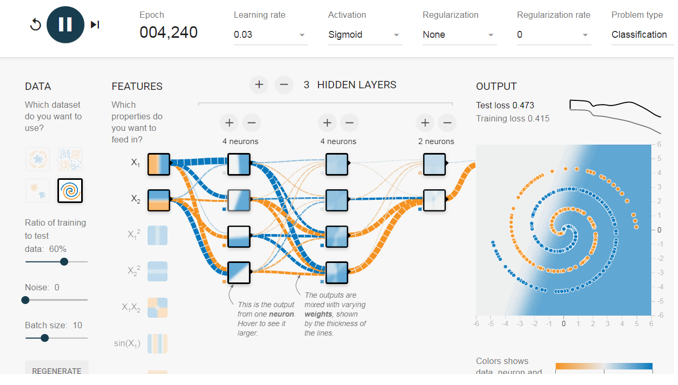

两个隐藏层，用Sigmoid激活函数，训练的批大小为10，学习率为0.01，在训练集上的损失是0.363，在测试集上的损失为0.468，我们可以调整特征的个数，迭代次数、学习速率、激活函数、隐藏层数和隐藏节点的个数等超参数，动态地观察分类效果。

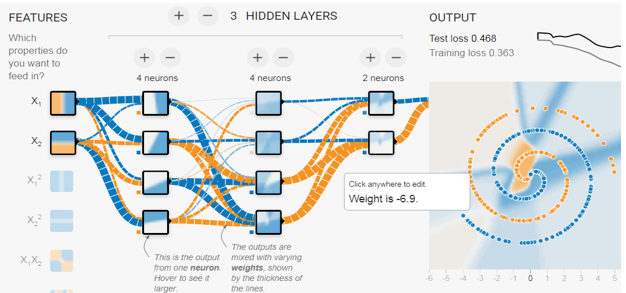

思考MLP网络训练中可能会存在哪些问题？

### 卷积神经网络及其应用

手写体识别案例中，对于图像数据而言，全连接网络的参数量巨大，不但占用空间多，也是容易**过拟合**的原因之一。

卷积神经网络，简称CNN，1998年LeCun推出了LeNet网络，它是第一个广为流传的卷积神经网络。CNN是深度学习技术中极具代表性的网络结构，应用非常广泛，尤其是在**计算机视觉**领域取得极大的成功。

卷积神经网络相比较于传统的图像处理算法的优点在于避免了对图像复杂的前期人工特征提取工作，CNN能直接从原始像素出发，经过少量的预处理，就能识别出原图视觉上的特征，有人也称其为**端到端**的学习。

2012年Hinton和他的学生推出了AlexNet。在当年的ImageNet图像分类竞赛中，AlexeNet以远超第二名的成绩夺冠，使得深度学习重回历史舞台，具有重大历史意义。

**卷积层**

由于卷积神经网络主要关注的是图像，所以卷积层和池化层的运算在概念上是处于二维平面的，同时这也是卷积神经网络与其他神经网络的不同点。

卷积层具有平移不变性，在图像右下角学到某个模式之后，可以在任何地方识别这个模式，比如左上角。只需更少的训练样本就能学到具有泛化能力的数据表示。

卷积核具有局部性，只对图像中的局部区域敏感。整个卷积过程相当于一层神经网络。

卷积层的作用类似于经典信号处理中的滤波器

卷积层的作用类似于经典信号处理中的滤波器。

下面的网站给出了边缘滤波效果图：https://graphics.stanford.edu/courses/cs178/applets/convolution.html

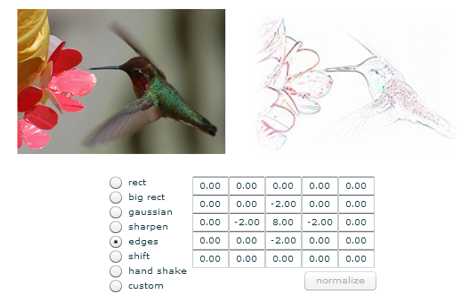

深度网络基本架构中，层是基本的数据结构，一个数据处理模块，可将层看作深度学习的乐高积木，Keras等框架就是这么做的，构建深度学习模型就是将相互兼容的多个层拼接在一起。

网络拓扑结构的选择更像是一门艺术而不是科学，只有动手实践才能成为合格的神经网络架构师。

 **LeNet-5** 

是由LeCun等人在1998年发表的，是卷积神经网络的开山之作。LeNet也是第一个成功应用于数字识别问题的卷积神经网络。在MNIST数据集上，LeNet-5模型可以达到大约99.2%的正确率。网络包含了卷积层、池化层、全连接层，这些都是现代卷积网络的基本组件。

LeNet-5模型总共有7层，下图展示了LeNet-5模型的结构。

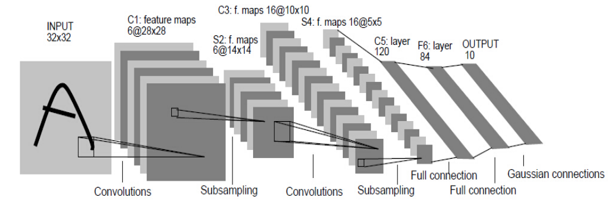

把LeNet算法结构图看懂了，其他任何卷积神经网络结构就基本上大体能理解了。相比MLP，LeNet使用了相对更少的参数，总共只有60000个参数，获得了更好的结果。

LeNet-5重大的突破在于，不再像经典的图像处理，需要人工预先设定卷积核(或称滤波器)，而是通过训练自动形成的，这就是伟大的自动特征提取。

以今天的观点来看，LeNet-5只有7层，算不上“深度”，第一个真正的深度神经网络，称之为深度学习革命的揭幕者：AlexNet。由Hinton带领的多伦多大学团队提出，相比LeNet-5，AlexNet设计了更深层的网络。

CIFAR图像集共有10类，飞机，汽车，鸟，猫，鹿，狗，青蛙，马，船，卡车。可以从网站下载数据集：http://www.cs.toronto.edu/~kriz/cifar.html，详细代码我们分享在github上：https://github.com/shixiangbupt/deeplearning

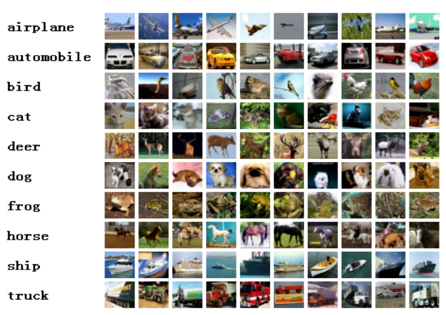

均方误差函数是一种常见的度量损失函数的方法，但不是唯一的

Neural Network Toolbox用于训练调用网络，且针对工具箱制作了非常精美可视化的app，用于构建，训练，可视化以及仿真神经网络。

可以使用它来进行分类，回归，聚类，降维，时间序列的预测以及动态系统建模与控制，工具箱封装了专门的数据结构和算法，以用于模型的构建训练和使用。

BP网络：前向神经网络

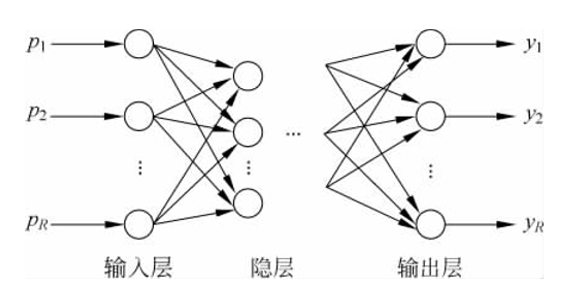

•误差逆传播(Error Back Propagation，BP)算法就是其中最杰出的代表，它是迄今最成功的神经网络学习算法，现实任务中使用神经网络时，大多是在使用BP算法进行训练。

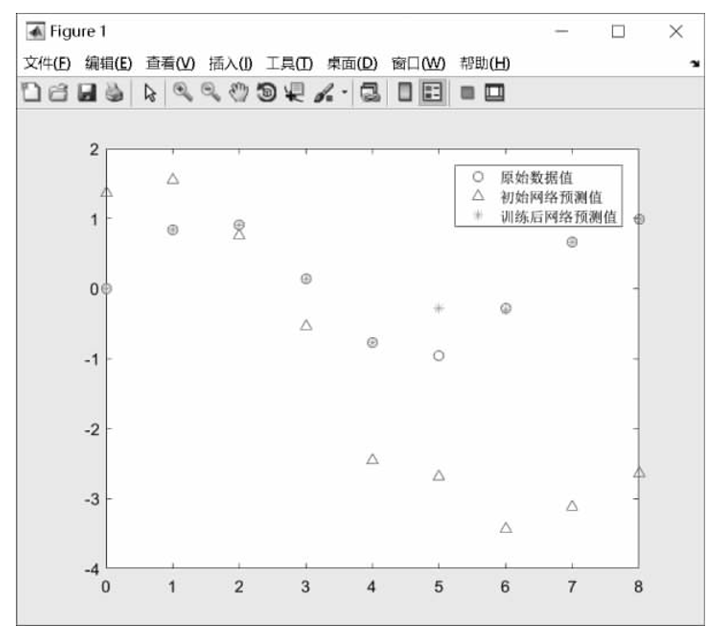

一、基本原理

现代计算机能快速，精确，稳定计算一系列预先设计好的运算，对重复性计算问题具有非常强大的处理能力，但并不能智能。

生物有智能的秘诀就隐藏在这些神经元及其连接之中。

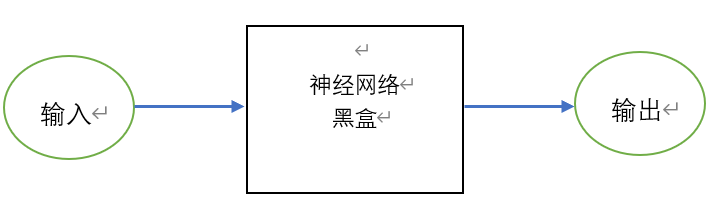

有些神经元负责接收外部环境的信息，有的负责对外部环境给出反馈，其他神经元负责处理这些信息，分input层，output层，hidden层神经元。

每个神经元都进行简单的计算，如果接收到的数值超过一定的阈值，则神经元转为激活状态并输出某个数值到下一层神经元，如果一个神经元被激活，则它将对下一层与其连接的所有神经元发送一个相同的数值，每个神经元都可看作一个缩放器，整个网络中所使有阈值(参数)都不需要预先设定，可以使用各种算法包括监督学习算法，非监督学习算法以及强化学习算法自动求解参数。

每层神经元都是相互独立的，并行的，可处理非常大的数据量。

从统计意义上讲，完成物体识别这种难度级别的任务，需要模型系统有极为优秀的处理噪声的能力。

人脑很难理解神经网络是如何得到结果的，模型称为黑盒模型啊，人们只能理解模型的输入和输出，而不能理解中间的运算过程。

隐藏层数量决定了神经网络大小，连接方式，目前没有理论可以指导何种结构的神经网络能适应何种问题，凭借主观经验。

输入层节点个数与样本特征向量的长度相同，每个神经元接收一个特征值作为输入数值，输出层节点个数取决于研究目标所需的个数。

过小的神经网络容易拟合不足，导致精度下降，大型的神经网络能极好地拟合训练集，但往往有过拟合的风险，另外，训练时间也很长。

训练方法：先前向传播计算结果，后反向传导误差梯度的形式更新网络中的连接权重，再通过调整连接权重来影响前向传播的计算结果，整个过程不断重复，直至参数收敛。

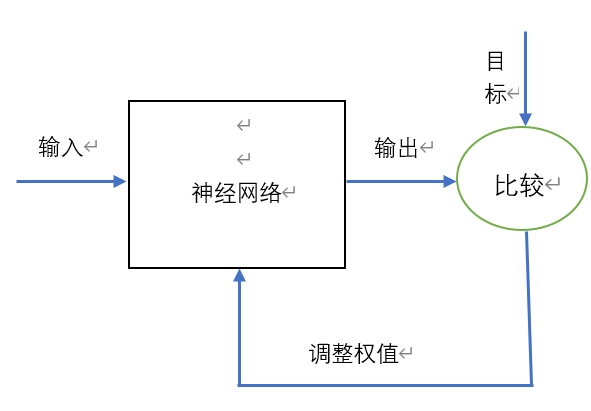

三、工具箱

封装了诸多算法，预训练模型及其可视化APP，可供用户训练，可视化和仿真神经网络。

GUI直接调用：命令行窗口中执行nnstart打开工具箱用户界面。可视化完成函数拟合nftool，模式识别nprtool，聚类分析nctool，时间序列分析ntstool

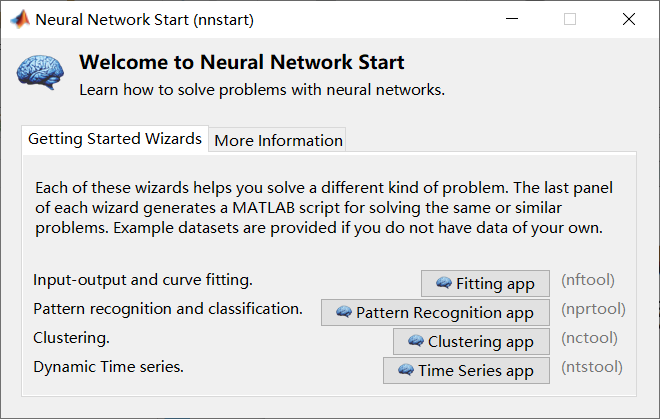

代码直接调用：GUI界面的本质就是通过图形化方式调用工具箱中封装好的函数，另一个好处就是非常简便，易于理解，学习。

用户定制神经网络结构：通过GUI界面甚至可以直接定制自己需要的网络结构。

更改工具箱源代码：对于极度复杂的问题，工具箱中的函数封装也不足以处理，可以直接更改源代码，工具箱中函数的源代码本身就是我们学习神经网络和在matlab中实现神经网络的绝佳资源。

步骤：

- 收集数据

- 构建神经网络

- 设置神经网络的相关参数

- 初始化权重参数和偏置项

- 训练神经网络

- 验证神经网络

- 测试神经网络

神经网络对象：保存定义的与神经网络相关的全部信息，属性值：General：网络宏观参数，Architecture：架构参数的数量(输入变量，层数，权重数据，输出变量，目标变量等)以及不同层间的连接。Subobject Structures：单元类型变量，保存输入变量，每层结构，权重数据，输出变量，目标变量等。 Functions：保存初始化，训练，评估网络使用的算法，函数信息。Weight and  bias values：保存权重参数。

第五步训练网络，算法会迭代地修改权重值和偏置项值，以渐进地优化神经网络表现，数据集指导样本以随机顺序输入模型进行训练，训练集占总数据的70%。验证集占15%，测试集15%(_泛化能力)。

训练集：用于求解模型参数，权重参数和偏置项。

验证集：衡量模型对训练集的拟合能力，若不足，则证明当前模型不具备拟合数据集的能力，需重新设计模型以进行训练和验证。

测试集：视为模型泛化能力的最终测试，能观察到过拟合，拟合不足问题，测试集表现是评估模型好坏，挑选最终模型的标准。

Matlab工具箱中的样例数据集

help nndatasets

  Neural Network Datasets
  -----------------------
 
  Function Fitting, Function approximation and Curve fitting.
 
  Function fitting is the process of training a neural network on a
  set of inputs in order to produce an associated set of target outputs.
  Once the neural network has fit the data, it forms a generalization of
  the input-output relationship and can be used to generate outputs for
  inputs it was not trained on.
 
   simplefit_dataset     - Simple fitting dataset.
   abalone_dataset       - Abalone shell rings dataset.
   bodyfat_dataset       - Body fat percentage dataset.
   building_dataset      - Building energy dataset.
   chemical_dataset      - Chemical sensor dataset.
   cho_dataset           - Cholesterol data

这些数据集中都会存在nameInputs，nameTargets这两个变量

load abalone_dataset

加载abaloneInputs和abaloneTargets到工作间

[Input,Target]=abalone_dataset;
%用其他变量名重新命名这两个变量


获取数据集详情：

help abalone_dataset

 abalone_dataset Abalone shell rings dataset.
 
  Function fitting is the process of training a neural network on a
  set of inputs in order to produce an associated set of target outputs.
  Once the neural network has fit the data, it forms a generalization of
  the input-output relationship and can be used to generate outputs for
  inputs it was not trained on.
 
  This dataset can be used to train a neural network to estimate the
  number of abalone shell rings from several attributes of the shell.
 
  LOAD abalone_dataset.MAT loads these two variables:
 
    abaloneInputs - an 8x4177 matrix defining eight attributes for 4177
    different shells.
 
      1. Sex: M, F, and I (infant)
      2. Length
      3. Diameter
      4. Height
      5. Whole weight
      6. Shucked weight
      7. Viscera weight
      8. Shell weight
 
    abaloneTargets - a 1x4177 matrix of ring counts for each shell.
 
  The number of rings of an abol

### 数据拟合

  根据数据框集中的样本和目标值的关系，使用数学模型构建从输入到输出的映射关系，即从数据集的样本中学习代表其映射关系的函数。

通过拟合的函数，应用插值法填补空缺的数据。

第一，数据集本身就非常复杂，难以拟合，第二，更常见，真实的数据在收集过程中无法避免会受到噪声污染。有些噪声是正常现象，代表了样本个体的特征，更加隐蔽的是，有些“噪声”的出现并非因为个体所造成的波动，问题背后的原因包含了诸多不为人所知的，无法观测到的变量，它们被误认为噪声，传统的统计学派模型难以应对这种级别的复杂度。

人工神经网络虽然在数学上极为简单，但通过大规模，层次化运算，具有极为强大的拟合能力，非常善于处理此类问题。

对于神经网络，所谓拟合就是指训练阶段通过输入数据集中的样本求解连接权重中的参数过程，一旦参数求解完毕，训练后的神经网络就是一个从输入数据到输出数据的映射函数，构建了从样本特征向量到目标值的映射关系。

simplefit_dataset:简单拟合场景的数据集

abalone_dataset:鲍鱼壳周长数据集

bodyfat_dataset:体脂数据集

building_dataset:建筑耗能数据集

chenical_dataset:化学物质探测器

cho_dataset:胆固醇数据集

engine_dataset:发动机

vinyl_dataset:乙烯溴化物

了解神经网络app规定的输入数据和目标数据的格式，指导我们对样本的收集。

#### 使用拟合app

包含一个隐藏层的前向传播神经网络建立从输入到输出的映射函数，信息只能向一个方向流动，即从输入层向输出层方向流动，中间不会出现环状链接。

>> nftool 

在训练阶段，只有连接的权重发生改变。

选择要拟合的数据集：Get Data from workspace:从工作间中获取数据；

另一种方式：load  Example Data Set

1) input data to present to the network: 需要输入神经网络的数据变量

2）Target data  defining  desired  network  output：神经网络的目标变量

这两个区域有下拉菜单，也可以单击省略号按钮。

初学者建议加载样例数据集进行学习，避免数据清洗格式整理等预处理工作。

单击：加载样例数据集，选engine数据集，基于发动机燃料和转速数据能预测发动机转矩的神经网络。

nftool


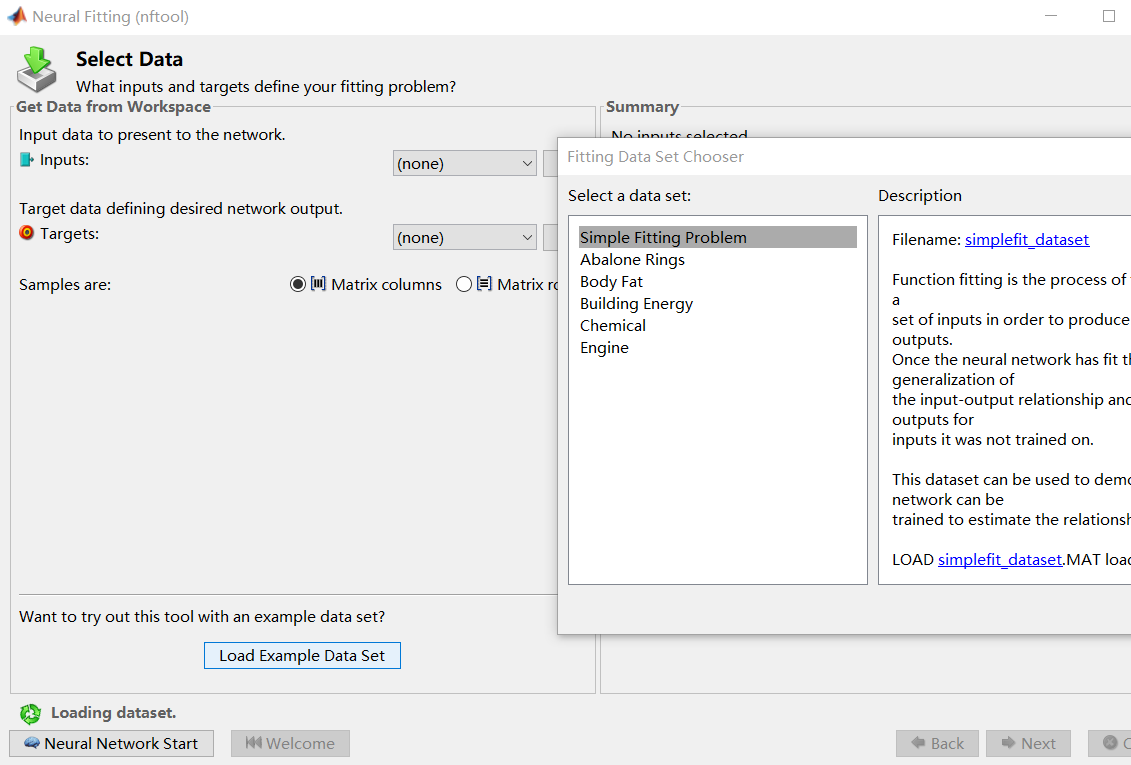

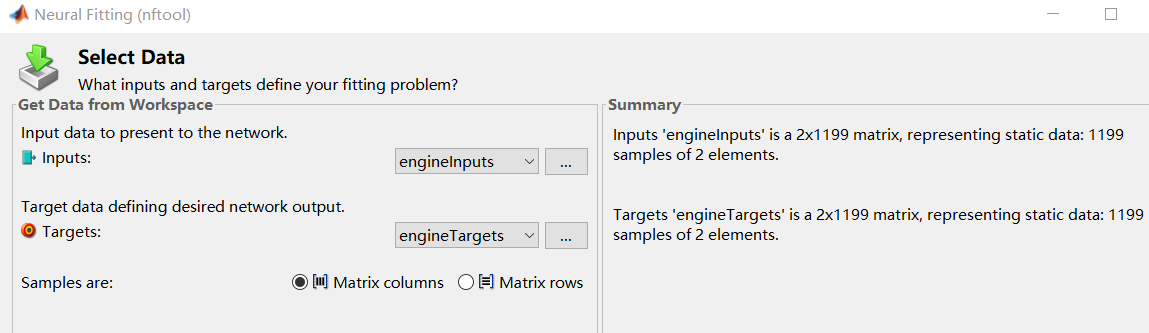

engineInputs :2*1199数值型矩阵，含燃料数据和速度数据这两个特征；

enginTargets:2*1199数值型矩阵，含预测的两个目标变量的扭矩和氮氧化物排放量

单击Next下一步：

在Validation and  Test  Data窗口中，工具箱自动对数据集进行分割，按70%，15%，15%比例讲数据集分为训练集，验证集，测试集3个部分。

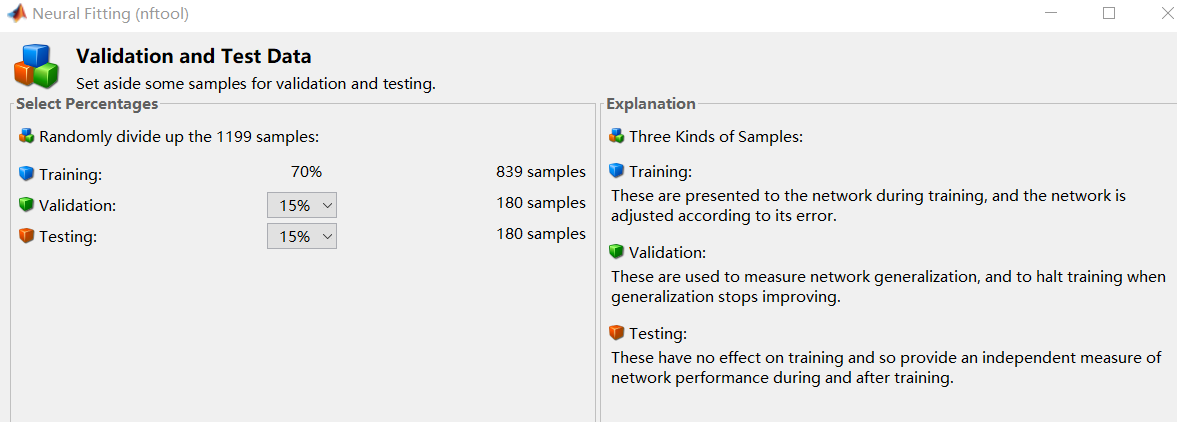

单击NEXT：进入Network Architecture ，默认的神经网络结构，包含一个隐藏层的前向传播神经网络，以sigmoid函数作为激活函数，输出层以简单的线性函数作为激活函数，其中隐藏层默认包含10个神经元，如果训练结果表现不好，可以通过增加神经元数量使训练集上的拟合效果得到改善。

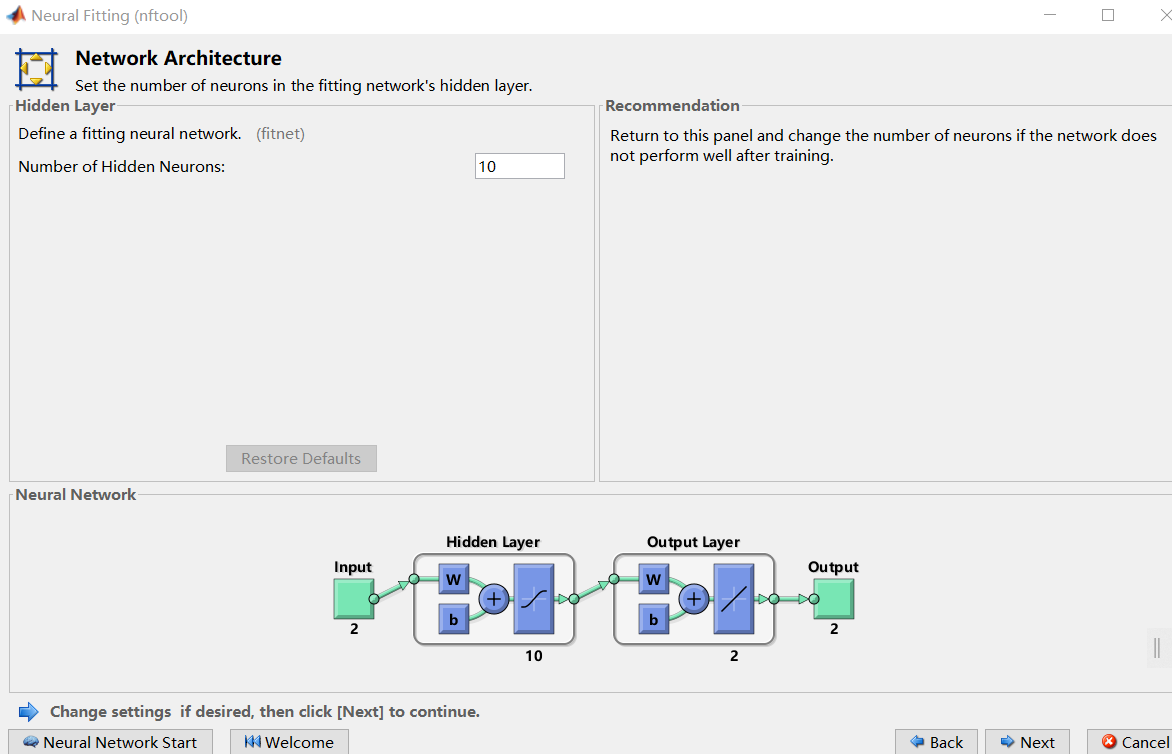

当然，过多的神经元又会出现过拟合问题。

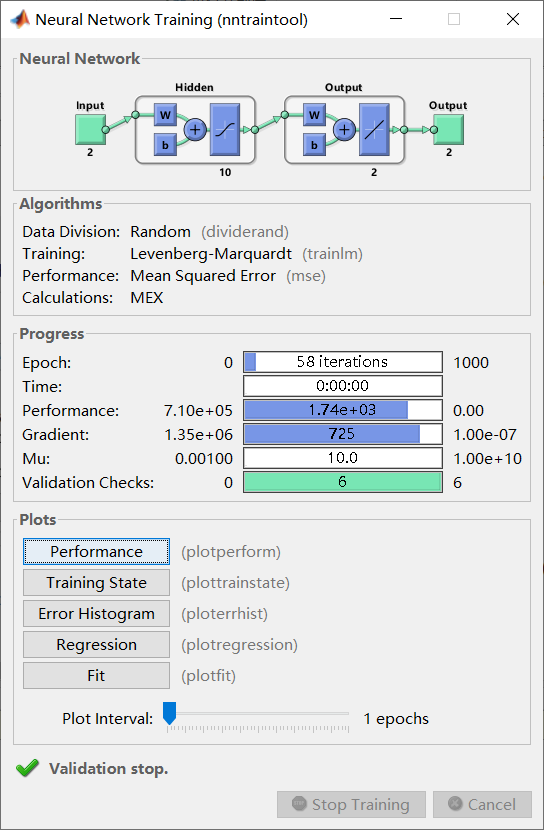

Next--> Train  Network

有三种算法可以作为神经网络的训练算法：

1） levenberg-Marquardt(trainlm):适用于绝大多数神经网络；

2） Bayesian  Regularization(trainbr):适用于小数据集，噪声较多的数据集，但训练时间更长。

3）Scaled  Conjugate  Gradie(Trainscg):适用于大数据集，这个算法以梯度作为神经网络更新权重的依据，而非雅可比矩阵，因此在内存使用的效率上效率更高。

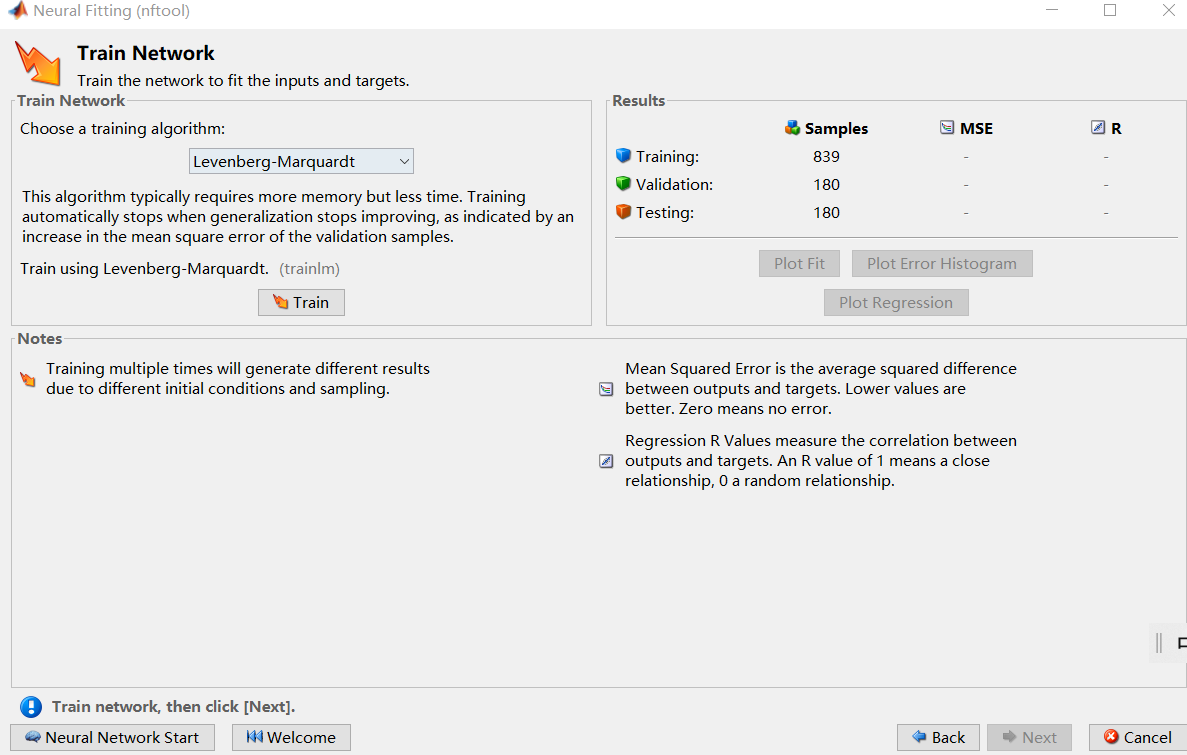

选第一训练算法，单击train按钮开始神经网络训练，训练过程不断迭代，直至验证误差连续6次迭代都不再下降，

训练结束后，Results区域中会显示验证集的MSE和R值作为对训练结果好坏的衡量。

Mean Squared  Error(MSE)是神经网络输出向量与目标向量加权平均后的均方误差，MSE越小，训练效果越好。

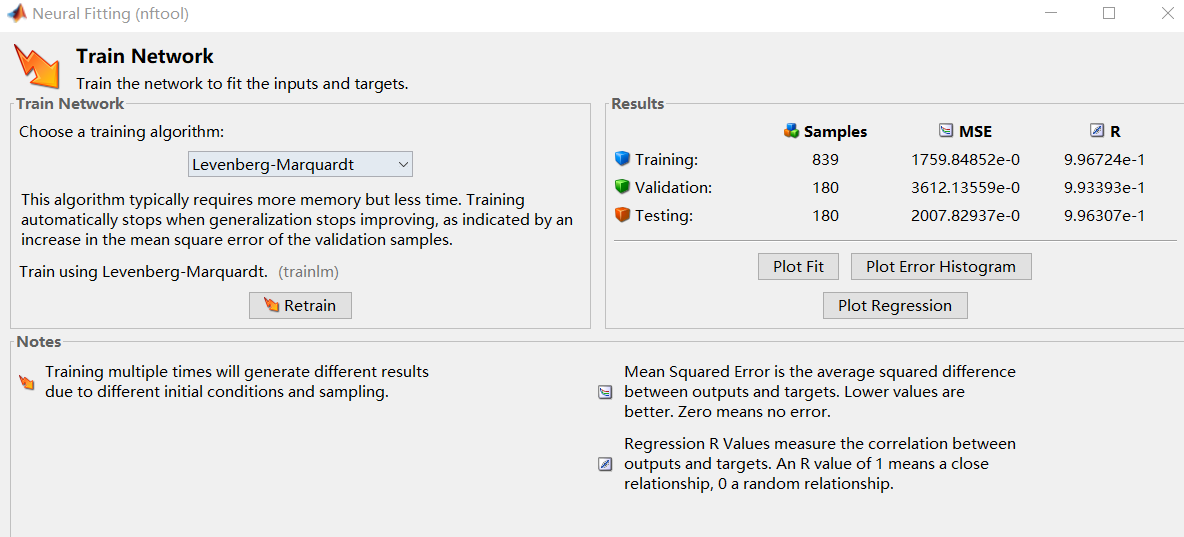

误差箱型图，蓝色条代表训练数据，绿色代表验证数据，红色代表测试数据，由此清楚地看到误差的分布状态，如果误差呈正态分布，则意味着训练结果较好。此外，误差柱状图也你能观测到奇异值，即训练误差显著大于平均水平的样本点。

如果对训练效果不满意可以重新训练。或者更改网络结构重新训练。

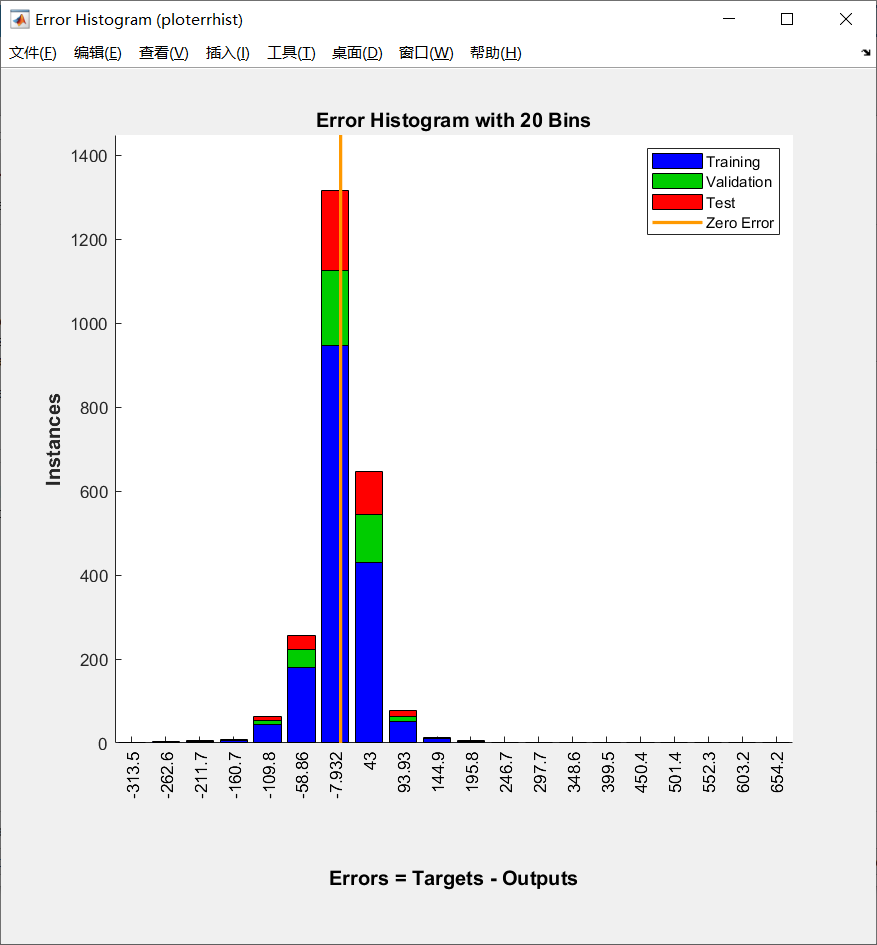

Regression® 则衡量输出向量与目标向量的相关性，1代表非常相关，0代表相关性极低，相关系数越大，训练效果越好。

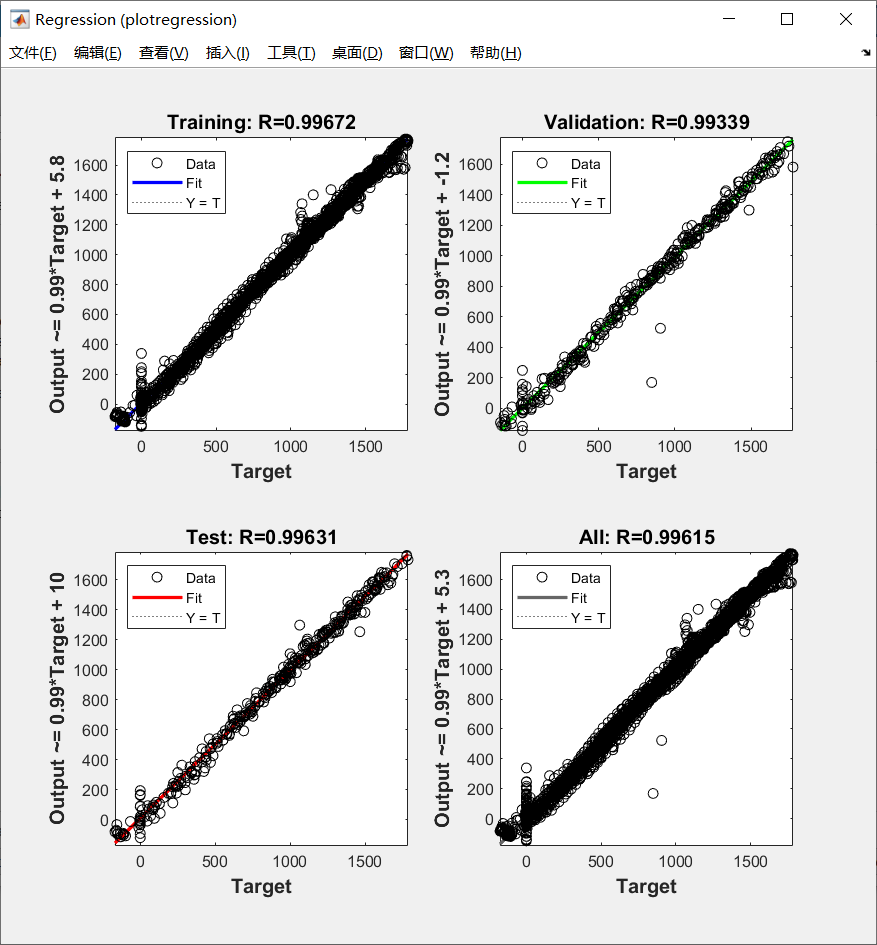

以目标向量为横轴，以输出向量为纵轴绘制的训练集，验证集，测试集及全体数据集中样本点相关性系数图。对一个表现优良的系统，相关性分布应尽可能靠近45度，即模型输出与目标值基本相等。

单击当前对话窗口中的next，打开Evaluate network窗口。通过在测试集上运行之前训练好的神经网络来评估当前神经网络泛化能力。

- 工具箱集成了多种评估泛化能力的方法；

- 加入新的数据并扩充现有的测试集以进行测试；

- 重新训练神经网络；

- 添加更多的神经元；

- 使用更大的训练集

与之前的模型相同，如果训练集，验证集上表现不好，可以通过增加神经元数量对结果进行改善，然而在训练集，验证集上有良好的表现，而在测试集上表现很差的神经网络则会出现对训练集的过拟合现象。可以通过减少神经元数量避免这一现象。如果交替出现以上两个问题，那么说明当前隐藏层的神经网络不足以拟合数据集，需要使用更加深度的神经网络进行拟合。

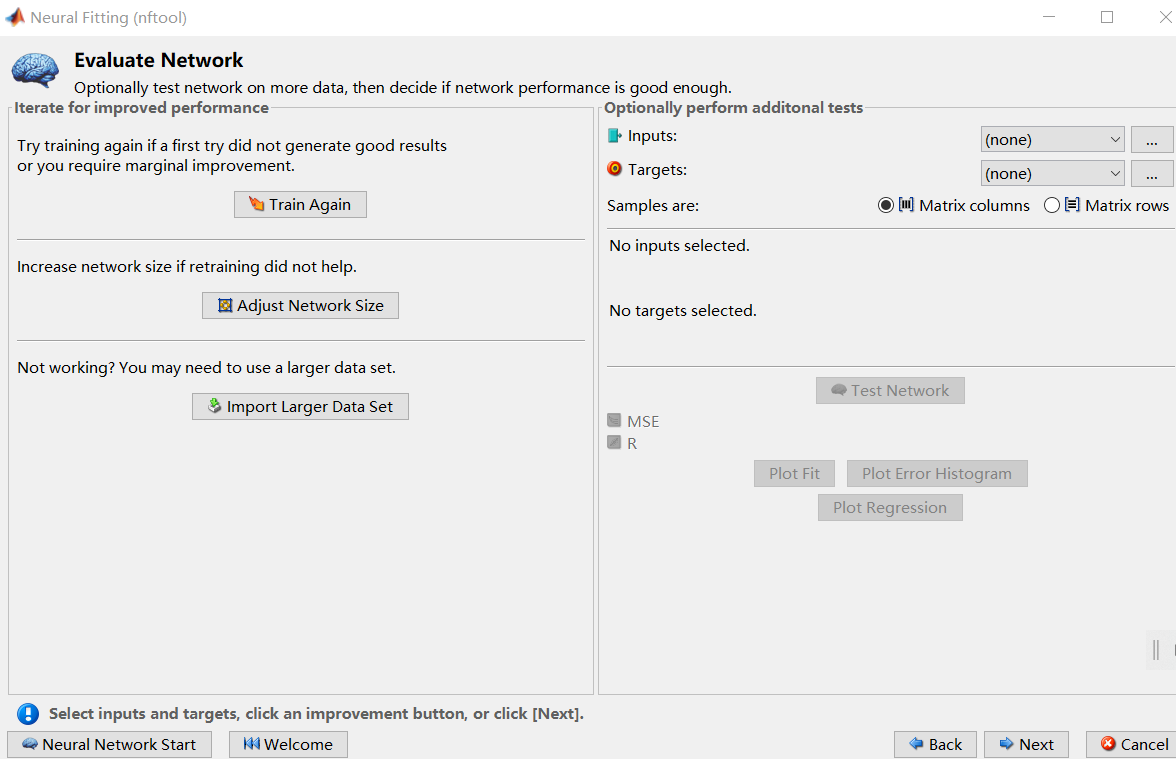

单击Next按钮，部署网络

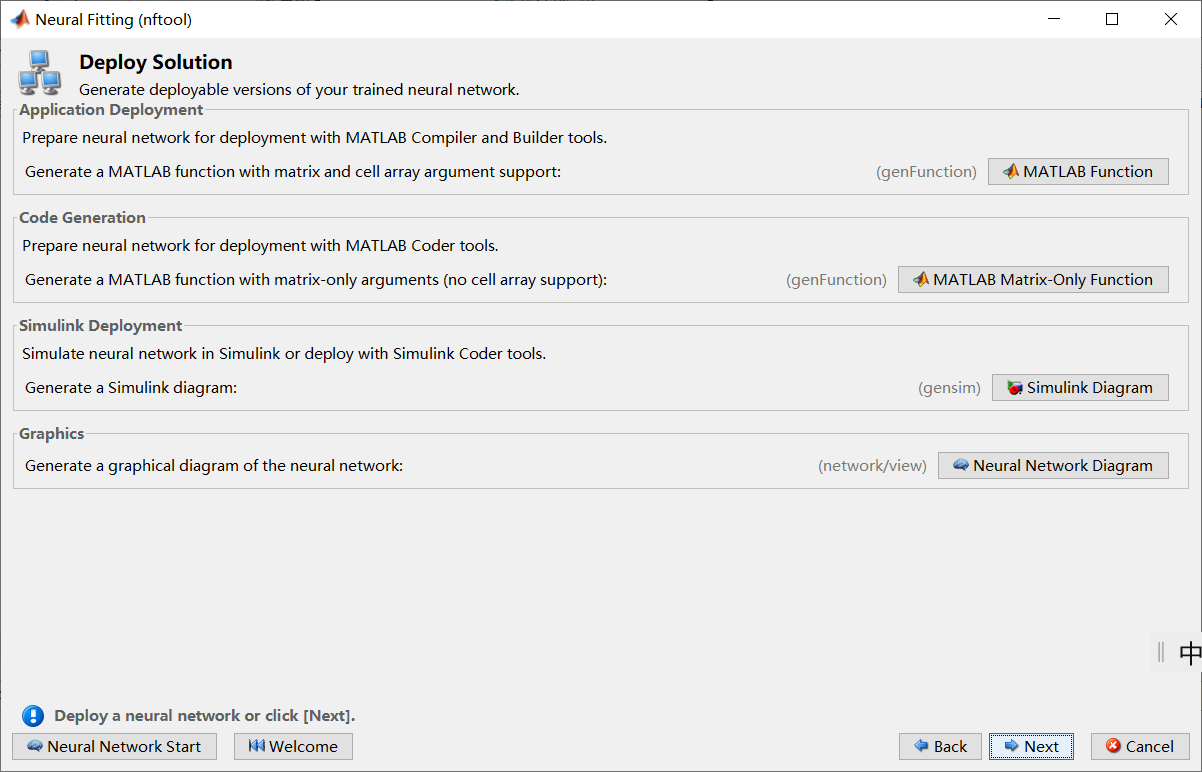

可以导出当前训练好的神经网络模型，以便能重复用于生成环境。有多种导出方式：

导出支持matrix和cell数据类型的matlab函数；

导出simulink图，导出神经网络结构图。

单击next，save results界面：

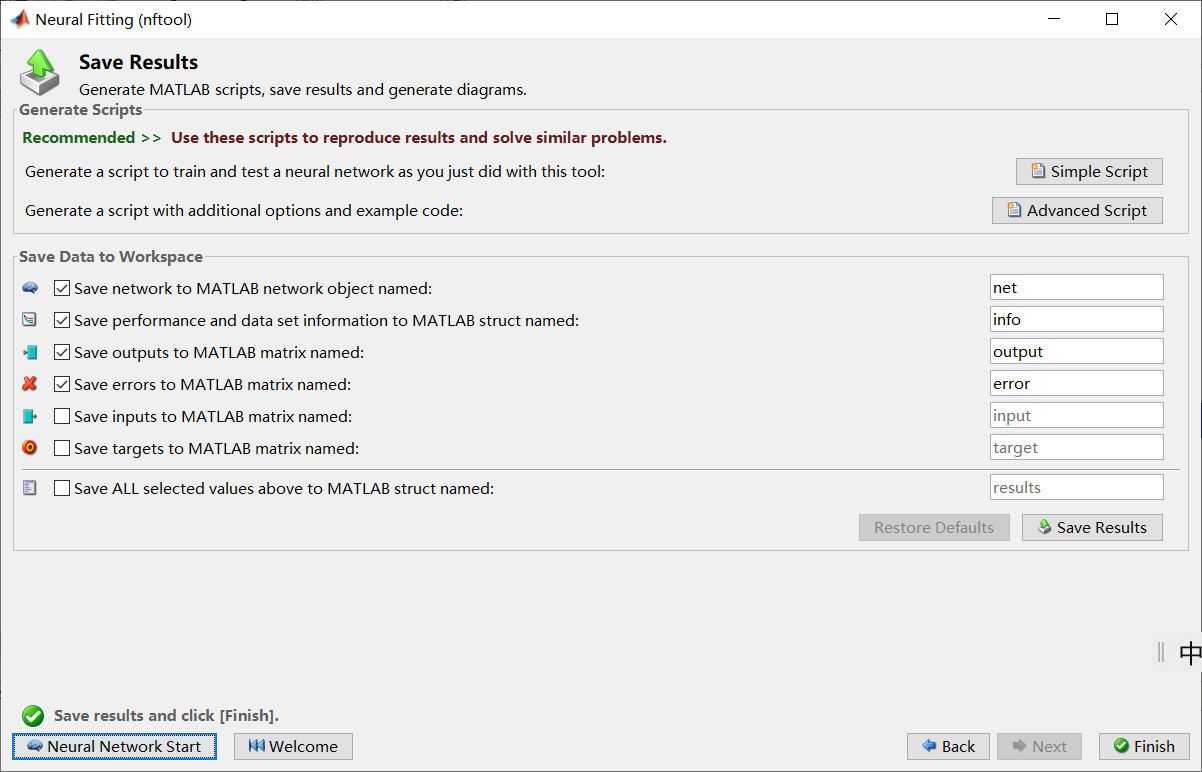

生成对应的matlab代码文件；

在脚本中添加其余设置及实例代码；

将数据保存在工作空间中。

虽然表面上是单击GUI与图形界面进行交互，但本质上是通过图形界面窗口对matlab已经封装好的工具箱函数进行可视化调用，调用结果与直接使用工具箱函数编写matlab代码产生的结果没有任何区别。

也就是说，通过研究与GUI的交互所产生的matlab代码，学会如何摆脱GUI直接使用工具箱函数编写程序，大大简化了学习难度。

### 脚本分析

x = engineInputs;

t = engineTargets;

trainFcn = 'trainlm';  % Levenberg-Marquardt backpropagation.

hiddenLayerSize = 10; %隐藏层单元神经元数量

net = fitnet(hiddenLayerSize,trainFcn);

% Setup Division of Data for Training, Validation, Testing

net.divideParam.trainRatio = 70/100; %划分3个数据集

net.divideParam.valRatio = 15/100;

net.divideParam.testRatio = 15/100;

% Train the Network

[net,tr] = train(net,x,t);

% Test the Network

y = net(x); 

e = gsubtract(t,y); % 误差

performance = perform(net,t,y) %泛化能力的指标

% View the Network

view(net)

% Plots

% Uncomment these lines to enable various plots.

%figure, plotperform(tr)

%figure, plottrainstate(tr)

%figure, ploterrhist(e)

%figure, plotregression(t,y)

%figure, plotfit(net,x,t)

### 应用案例

建立一个以混凝土制作配方为输入数据，能够预测其承重能力的模型。

以下指标：

1） Cement 单位：kg/m^3

2) Blast  Furnace  Slag 单位：kg/m^3

3) Fly Ash 单位：kg/m^3

4） Water 单位：kg/m^3

5） Superplasticizer 单位：kg/m^3

6） Coarse  Aggregate 单位：kg/m^3

7） Fine Aggregate 单位：kg/m^3

8） Age 单位：kg/m^3

9） 输出指标包括Concrete  compressive  strength 单位：MPa

从主页菜单下Import Data按钮导入数据，

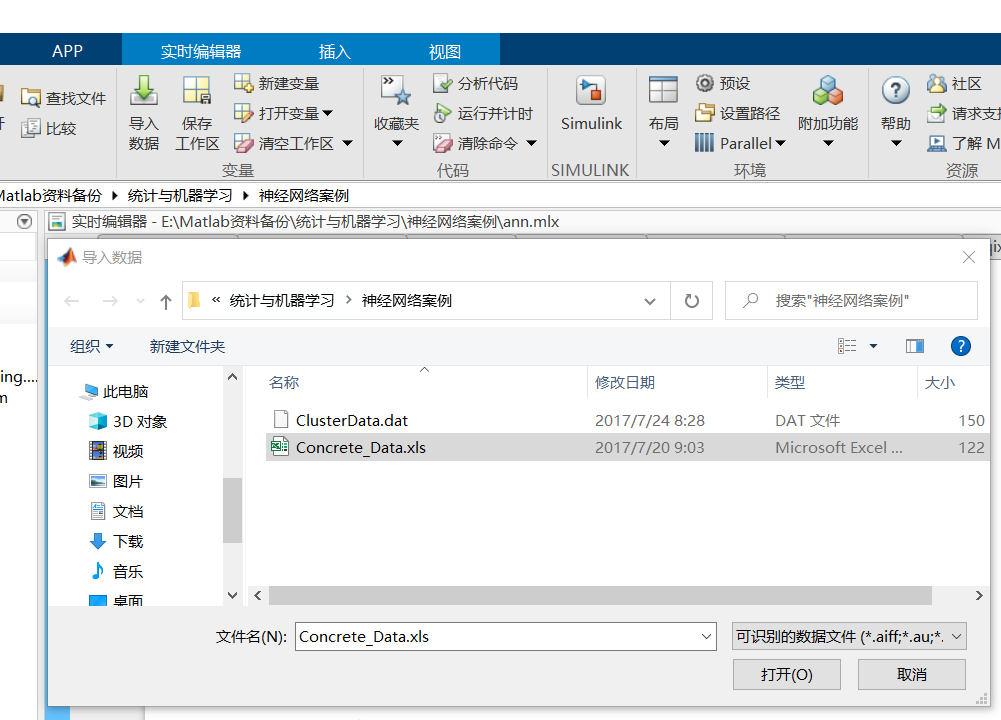

在导入数据类型中可以选择

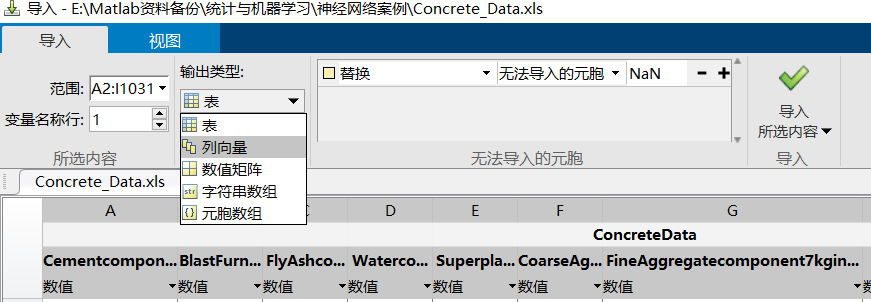

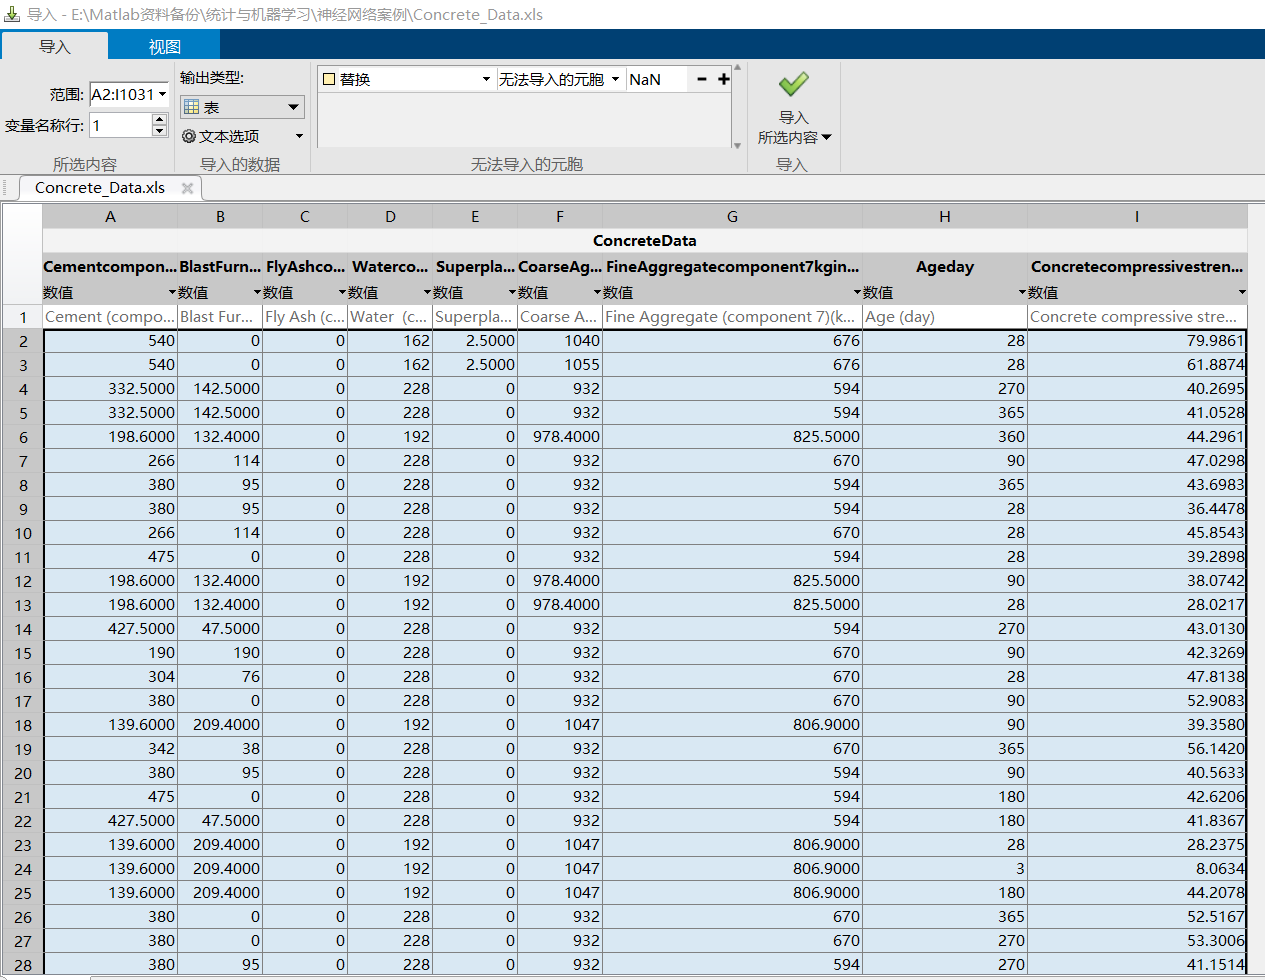

可以选择导入哪些变量，或者直接导入全部数据，这里选择表类型，导入后，工作间可以看到table类型的变量ConcreteData已经在工作间里。大小是1030*9，1030个样本，9个变量列，即8个特征值和1个目标值。

导入工具为这些特征值和目标值创建了列名，这些列名是原来excel文件中的表头名。

 ConcreteData = readtable('Concrete_Data.xls');

summary(ConcreteData)


Variables:

    Cement_component1__kgInAM_3Mixture_: 1030×1 double

        Properties:
            Description:  原始列标题: 'Cement (component 1)(kg in a m^3 mixture)'
        Values:

            Min                         102                
            Median                    272.9                
            Max                         540                

    BlastFurnaceSlag_component2__kgInAM_3Mixture_: 1030×1 double

        Properties:
            Description:  原始列标题: 'Blast Furnace Slag (component 2)(kg in a m^3 mixture)'
        Values:

            Min                                0                     
            Median                            22                     
            Max                            359.4                     

    FlyAsh_component3__kgInAM_3Mixture_: 1030×1 double

        Properties:
            Description:  原始列标题: 'Fly Ash (component 3)(kg in a m^3 mixture)'
        Values:

           

这个数据集无缺失值，接着对数据集进行可视化处理，得到对数据本身和数据间相关性的粗略认识。首先以承重能力作为纵轴，以特征值作为横轴，绘制每个样本中8个特征值的散点图矩阵。需要将table类型的变量转换为array类型后再绘制。

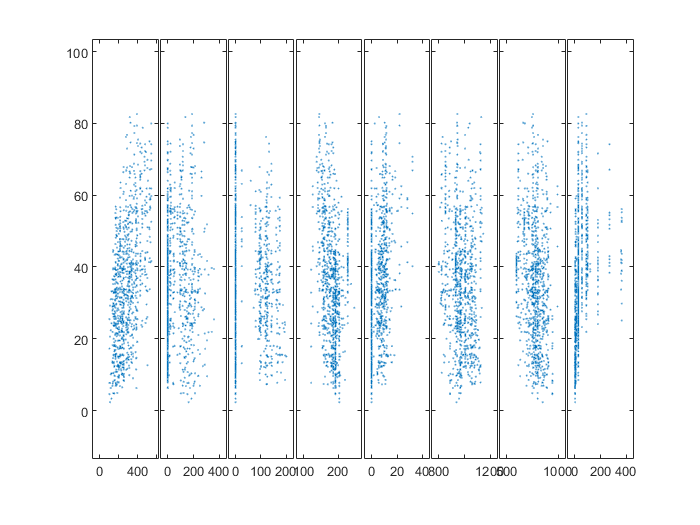

X = table2array(ConcreteData(:,1:8));
Y = table2array(ConcreteData(:,9));
plotmatrix(X,Y)

目前，很难从散点图中获取有用的信息。

承重和原料配方之间存在高度的非线性关系。考虑用神经网络来拟合。

找一个能以最高精度实现从输入数据到输出数据映射的数学函数。建立一个最小化拟合误差最大程度克服样本中的随机噪声，实现从输入到输出数据映射的回归方程。

前面将特征矩阵(前8列)，与目标值(混凝土强度)分离出来了，将其保存在两个矩阵X和Y中。

注意原始数据中保存数据的方式是每行代表一个样本，每列代表一个特征值。但是，神经网络工具箱中的函数恰好相反，默认输入数据的每列代表一个样本，每行代表一个特征值。

X = X';
Y = Y';

现在X仍然表示特征矩阵，Y仍然表示目标向量。

设置net.trainFcn属性更改神经网络训练算法

%help  nntrain

trainFcn = 'trainlm';%前面讲过有三种算法

%默认使用Levenberg-Marquardt作为反向传播算法

hiddenLayerSize = 10; % 大小为10个神经元的隐藏层
net = fitnet(hiddenLayerSize,trainFcn);
view(net)

以上只是定义了网络的结构，还没有对神经网络执行任何输入，输出，训练等运算。

为构建回归方程，需要使用函数fitnet()建立相应的神经网络，这个神经网络将返回一个用于回归拟合的，隐藏层为hiddenLayerSize的前向传播神经网络。

view()函数可视化神经网络图形，注意到现在输入输出都为零。

正式的机器学习模型运输前，首先要对原始书记进行预处理，以避免缺失值，奇异值等问题对模型产生不良影响。这里对数据去量纲化，即标准化，正则化处理。

神经网络工具箱提供了下列函数：

- fixunknows：保留缺失值

- mapminmax：将特征值矩阵标准化到[-1,1]区间

- mapstd：将特征值标准化到正态分布

- processpca：使用主成分分析进行数据预处理

- removeconstratrows：删除包含常量的行

net.input.processFcns = {'removeconstantrows','mapminmax'};
net.output.processFcns = {'removeconstantrows','mapminmax'};

常量的特征值对任何机器学习算法而言不具备学习意义。

下一步划分数据集，大部分机器学习算法，都通过有限的数据集对问题进行拟合，并从中学习潜在的模式。

在训练阶段，模型精度是通过计算模型的输出结果与真实值的误差得到的。任何机器学习模型的最终应用都是输入模型在训练阶段通过没有见过的样本的特征向量，对目标值给出预测的。模型在这个过程中的表现体现了模型的泛化能力，即模型通过学习历史数据对未知数据进行预测的能力。过拟合问题指的是模型在训练集上具有很好的拟合精度，但在测试集(即新样本上)的预测表现极差。--*有的同学，平时学的很好，但一到考试就垮了。*

为避免模型在训练阶段出现过拟合，研究者设计了一套分阶段，分数据集的训练方法，以便能在出现过拟合现象时及时识别，甚至在过拟合前预先停止训练。这套方法的核心概念在于将整个原始数据集划分为3个数据集：训练集，验证集，测试集。

训练集：训练集中的样本用于求解模型参数。对神经网络而言，即为权值参数和偏置项；

验证集：在训练完毕后，验证集中的样本将作为输入参数，模型在验证集上 的表现用于衡量模型对训练集的拟合能力。如果验证集表现不足，则证明当前模型不具备拟合数据集的能力，需要重新设计模型以进行训练，验证。

测试集：模型在训练集样本上的表现被视为对模型泛化能力的最终测试。通过观测测试集误差，我们能够观测到过拟合，拟合不足等问题。测试集的表现是评估模型好坏，挑选最终模型的标准。

通常在训练过程中，前几个迭代是在训练集，验证集上误差下降最快的迭代。如果出现过拟合现象，往往只有在训练集上误差不断下降，而验证集上的误差反而上升。

matlab提供了4种划分3个数据集的方法：

- dividerand：默认，随机划分

- divideblock：将样本按原始数据集中的顺序连续地分3块

- divideint：用插入法对数据集进行划分

- divideind：按照样本行数进行划分；

神经网络对象net有很多属性，通过改变这些属性，可以深度定制模型，算法等参数。

net.divideFcn %划分算法

net.divideParam:%算法参数

net.divideMode:默认为sample，划分目标向量的方法

net.divideFcn = 'dividerand';  
net.divideMode = 'sample';  
net.divideParam.trainRatio = 70/100;
%3个数据集的划分比例
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

接下来设置衡量神经网络拟合精度的指标。

- mae：绝对均值误差

- mse：均方误差

- sae：绝对误差和

- sse：平方误差和

- crossentropy：交叉熵

- msesparse：使用2范数作为误差函数且使用1范数作为正则化项，以保证稀疏性的均方误差

net.performFcn = 'mse';%选择mse均方误差

选择将对模型训练过程中用到的可视化结果的相关参数进行设置，可视化训练过程。

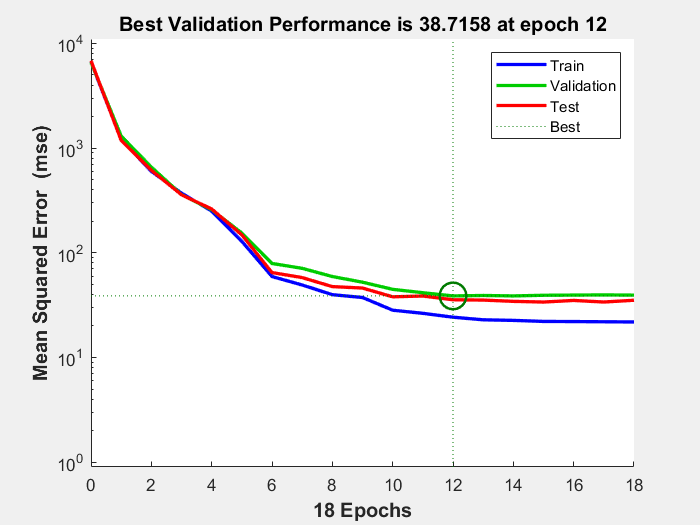

%help nnplot
net.plotFcns = {'plotperform','plottrainstate','ploterrhist', 'plotregression', 'plotfit'};
[net,tr] = train(net,X,Y);
figure, plotperform(tr)

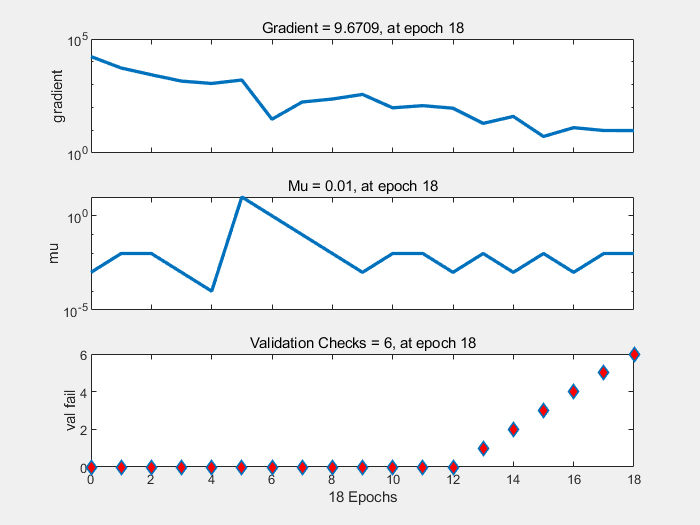

figure, plottrainstate(tr)

设置好后，用train函数训练网络，net参数指神经网络对象，tr训练记录：即每个epoch（训练集中全部样本被学习了一次，标为一个epoch，（整个过程需要反复对全部训练集数据学习多次哦，直到达到停止条件的 表现指标）。

在训练神经网络时，系统会自动弹出一个可视化窗口，其中显示与训练相关的各种数据。4类数据：神经网络结构，训练算法，训练过程以及根据各种指标绘制的图表。

神经网络结构区域显示了正在训练的神经网络结构图，输入层有9个神经元，输出层1个输出神经元。

训练算法区域显示了训练过程中一些非常重要的参数，如数据集的划分方法-dividerand，选用的训练算法--trainlm，衡量模型参数表现指标--mse.训练过程中可以看到训练的实时进展。最后的绘图区域，列出了可以绘制的所有图片类型及其对应的按钮。

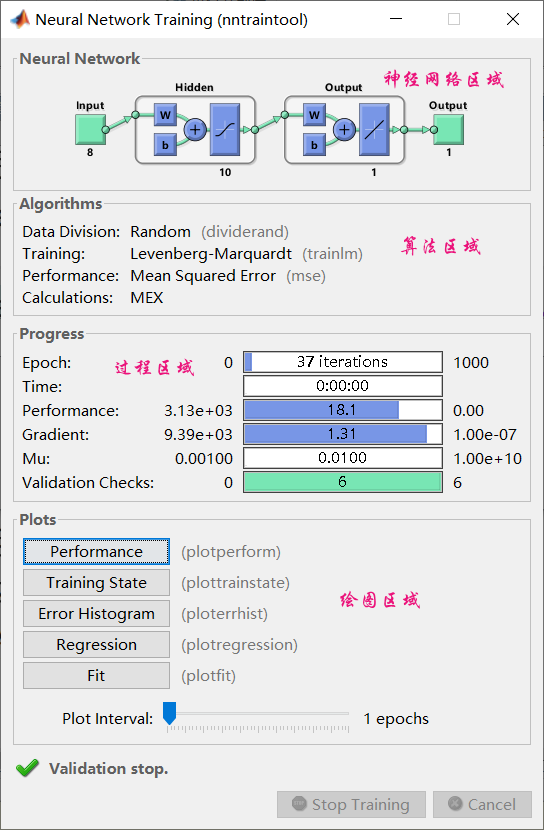

函数train会返回net和tr这两个变量，第一个是神经网络对象，第二个则记录了整个训练过程中的各种指标。可以通过plotperform()查看训练过程中衡量神经网络表现的各种指标的变化过程。

即plotperform(tr)绘制了神经网络精度(均方误差)在各个数据集上的变化过程。训练窗口的绘图区域中第二个图是训练状态图(plottrainstate(tr))

至此，神经网络已经训练完毕，可以将其应用到实际数据集中了。之所以训练神经网络，是为了构建一个模型，用于通过混凝土的制作配方预测混凝土的承受能力。

为了检验模型的预测效果，可以先把已有的数据集重新输入网络，对已有的数据集进行预测，并将预测结果与这些数据集的真实指标进行比较。通过这种比较就能得出，神经网络预测能力初步结果。

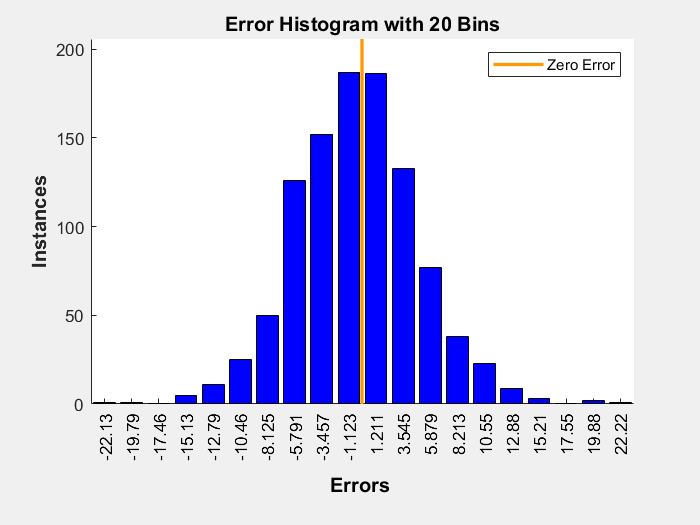

Ytest = net(X);
e = gsubtract(Y,Ytest);
performance = perform(net, Y,Ytest);
figure, ploterrhist(e)

上面第一行代码，用刚刚训练好的网络对象net对整个数据集X进行预测，并将结果保存称变量Ytest。第二行代码则用函数gsubtract()计算神经网络预测结果Ytest和真实目标向量Y之间差值，并将其作为神经网络的预测误差向量e。通过这种方法，得到了神经网络对每个样本的预测误差值。

最后一行代码通过使用函数perform()，根据之前定义的指标net.performFcn对模型进行。有多种方法可以衡量预测误差e，这里只是其中一种。

绘制网络预测误差e向量的箱型图。

figure ,ploterrhist(e)

可以用plotregression()函数来评估神经网络对目标向量拟合结果的好坏。这个函数使用线性函数以神经网络预测结果为输入向量，对真实目标向量进行线性拟合。

案例2：使用神经网络诊断甲状腺疾病

加载数据：

load thyroid_dataset;
InputData = thyroidInputs;%先对输入输出变量进行定义
TargetData= thyroidTargets;

- thyroidInputs大小为21*7200的矩阵，包含了7200个病人的生理指标，包括15和二元指标，6个连续性指标

- 大小为3*7200的矩阵，类别标签使用1在3行中进行标注，如果1出现在第一行，则表示诊断结果正常，如果1出现在第二行，则表示病人被诊断为甲亢，如果1出现在第三行，为甲减。

目前的困难在于如何识别甲减病人，因为数据集中只有8%的病人被诊断为甲亢，所以一个性能优良的分类模型必须能够成功诊断甲减。

help  nntrain %查看帮助

选择共轭梯度下降算法

trainFcn = 'trainscg';

隐藏层单元数10个

hiddenLayerSize = 10;

创建分类网络

net = patternnet(hiddenLayerSize, trainFcn);

分类网络同样是前向传播神经网络，但它的输出层可以有任意多个神经元，用于满足多分类任务。神经网络的目标向量是每个样本的对应类别标签为1，其余元素为0的矩阵。

切分数据集：

net.divideFcn = 'dividerand';  
net.divideMode = 'sample';  
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

performFcn衡量指标，默认为交叉熵函数，计算预测结果和真实值两者的交叉熵

net.performFcn = 'crossentropy';

选择绘制如下图表对训练过程进行可视化：

net.plotFcns = {'plotperform','plottrainstate','ploterrhist', 'plotconfusion', 'plotroc'};
[net,tr] = train(net,InputData,TargetData);

在训练网络时，系统自动打开训练窗口，显示与训练相关的各种数据。看懂这些数据，理解训练过程中发生了什么至关重要。

为了评估训练后神经网络的预测能力，可以使用训练后的神经网络对数据集进行预测，再将预测结果与真实目标矩阵进行比较：

OutputData = net(InputData);
e = gsubtract(TargetData, OutputData);
performance = perform(net, TargetData, OutputData);

这三行代码与前面例子一样。

TargetInd = vec2ind(TargetData);
OutputInd = vec2ind(OutputData);
percentErrors = sum(TargetInd ~= OutputInd)/numel(TargetInd);

vec2ind()作用与之前所说的使用1在三行中作为标记以表示样本属于哪个类别标签的目标矩阵TargetData相同，它转化为一个以数字1，2，3作为标签的向量。前一种矩阵更适用于神经网络拟合，后一种向量更适合于计算神经网络预测能力指标。最后一行代码计算了以百分制衡量的分类误差。

接下来将提取3个数据集(训练集，验证集，测试集)的预测结果和真实结果，以区分下面数据集的模型表现衡量：

trOut = OutputData(:,tr.trainInd);
vOut = OutputData (:,tr.valInd);
tsOut = OutputData (:,tr.testInd);
trTarg = TargetData(:,tr.trainInd);
vTarg = TargetData (:,tr.valInd);
tsTarg = TargetData (:,tr.testInd);

下面代码将对3个数据集和总数据集的混淆矩阵绘制图像：

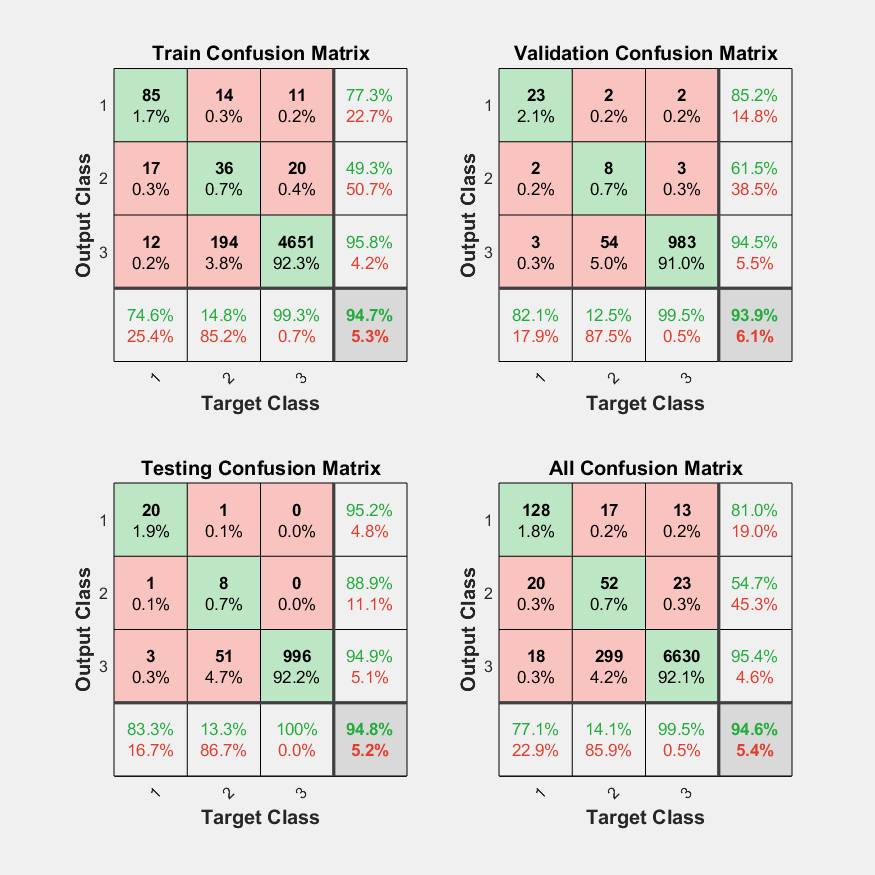

figure, plotconfusion(trTarg, trOut, 'Train', vTarg, vOut, 'Validation', tsTarg, tsOut, 'Testing', TargetData,OutputData,'All')

通过混淆矩阵，能够评估神经网络对真实数据集的预测能力，这种矩阵能够显示模型所犯的各种类型错误的细节。对角线上的元素显示的是预测正确的样本数量，其余元素是错误分类的样本数。

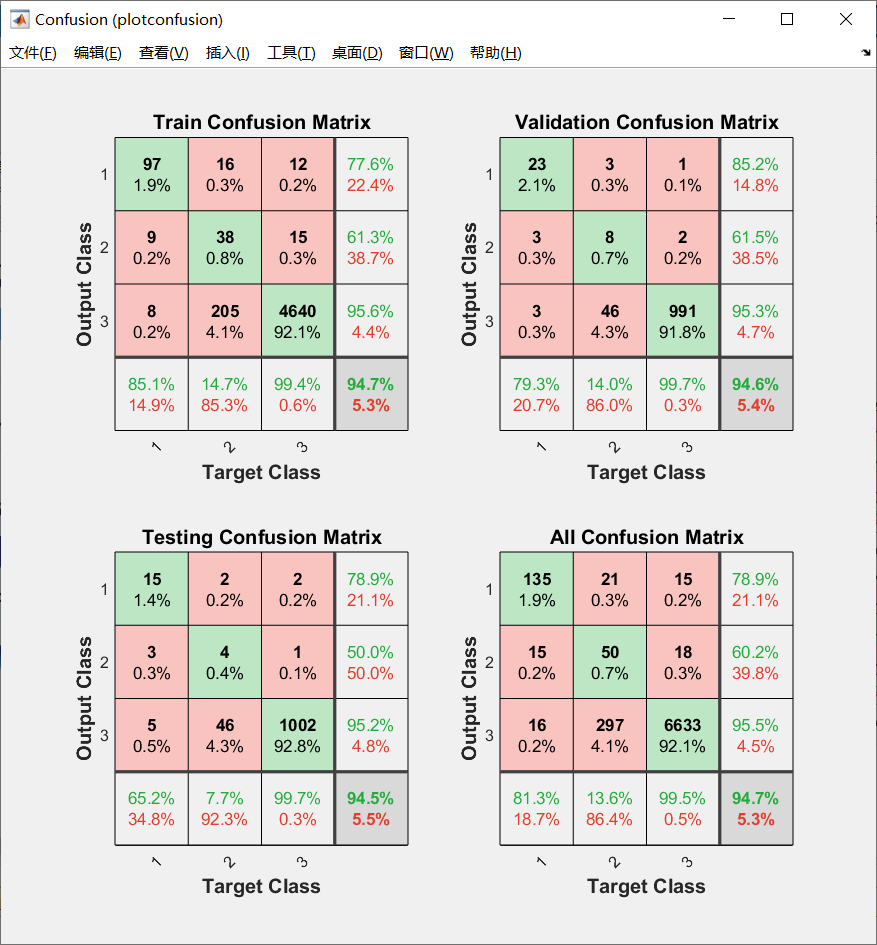

理想情况下，机器学习能够对健康，生病两种状态进行精确的预测，即没有样本会被错分到另一类别中。然而现实情况是，经常有生病的患者被预测为健康，或者相反。

因为是三分类问题，混淆矩阵是3*3矩阵。矩阵横坐标表示的是样本的真实值，纵坐标表示的是神经网络预测的结果。左上角第一幅图第一列告诉我们，有97个样本被正确分类为第一类(正常),9个第一类的样本被神经网络分类到了第二类(甲亢)，8个被分到第三类。

我们可以看到网络在测试集上仍然有非常好的分类精度(94.5%的正确率)，因此，可以认为这个神经网络已经具备了很好的泛化能力。如果需要更高的精度，则可以修改之前的参数，重新训练网络。

除了混淆矩阵，另一个衡量标注是受试者工作特征曲线(Receiver  Operating  Characteristic,ROC).为每个数据集及总数据集绘制受试者工作特征曲线。

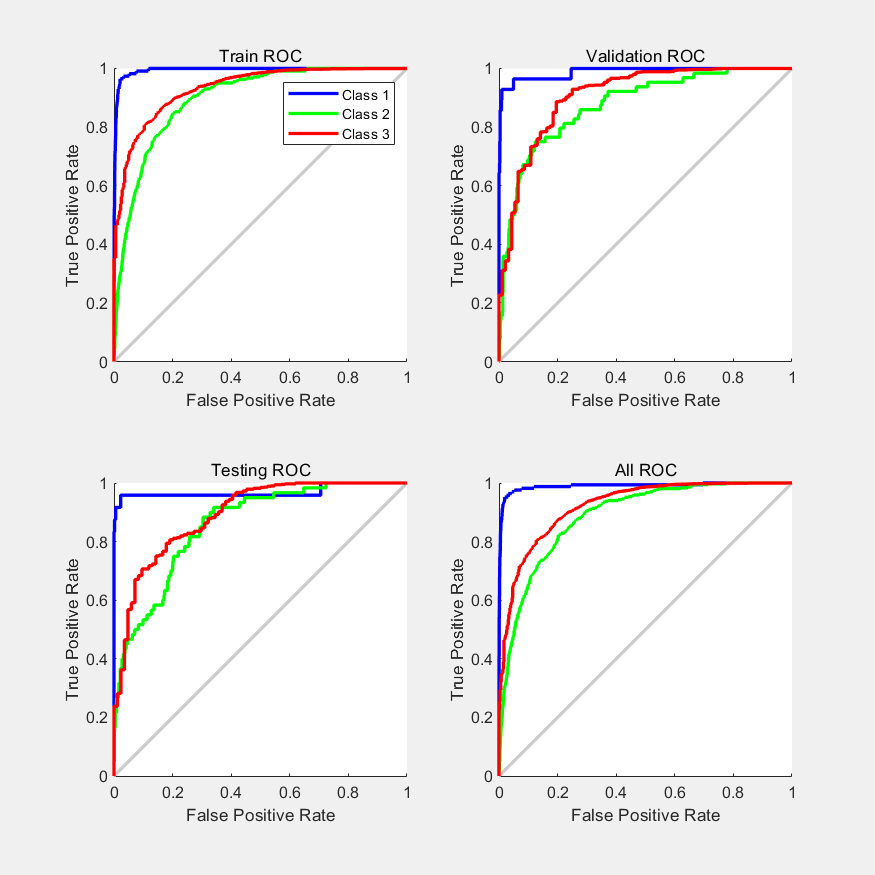

figure, plotroc(trTarg, trOut, 'Train', vTarg, vOut, 'Validation', tsTarg, tsOut, 'Testing', TargetData,OutputData,'All')

matlab对不同类别的曲线使用不同颜色进行标注。ROC曲线绘制了TP(True Positive )样本数量对FP(False Positive)样本数量的比值，若曲线越向左上角凸，说明对改类别的分类精度越高。

### 动手练习 

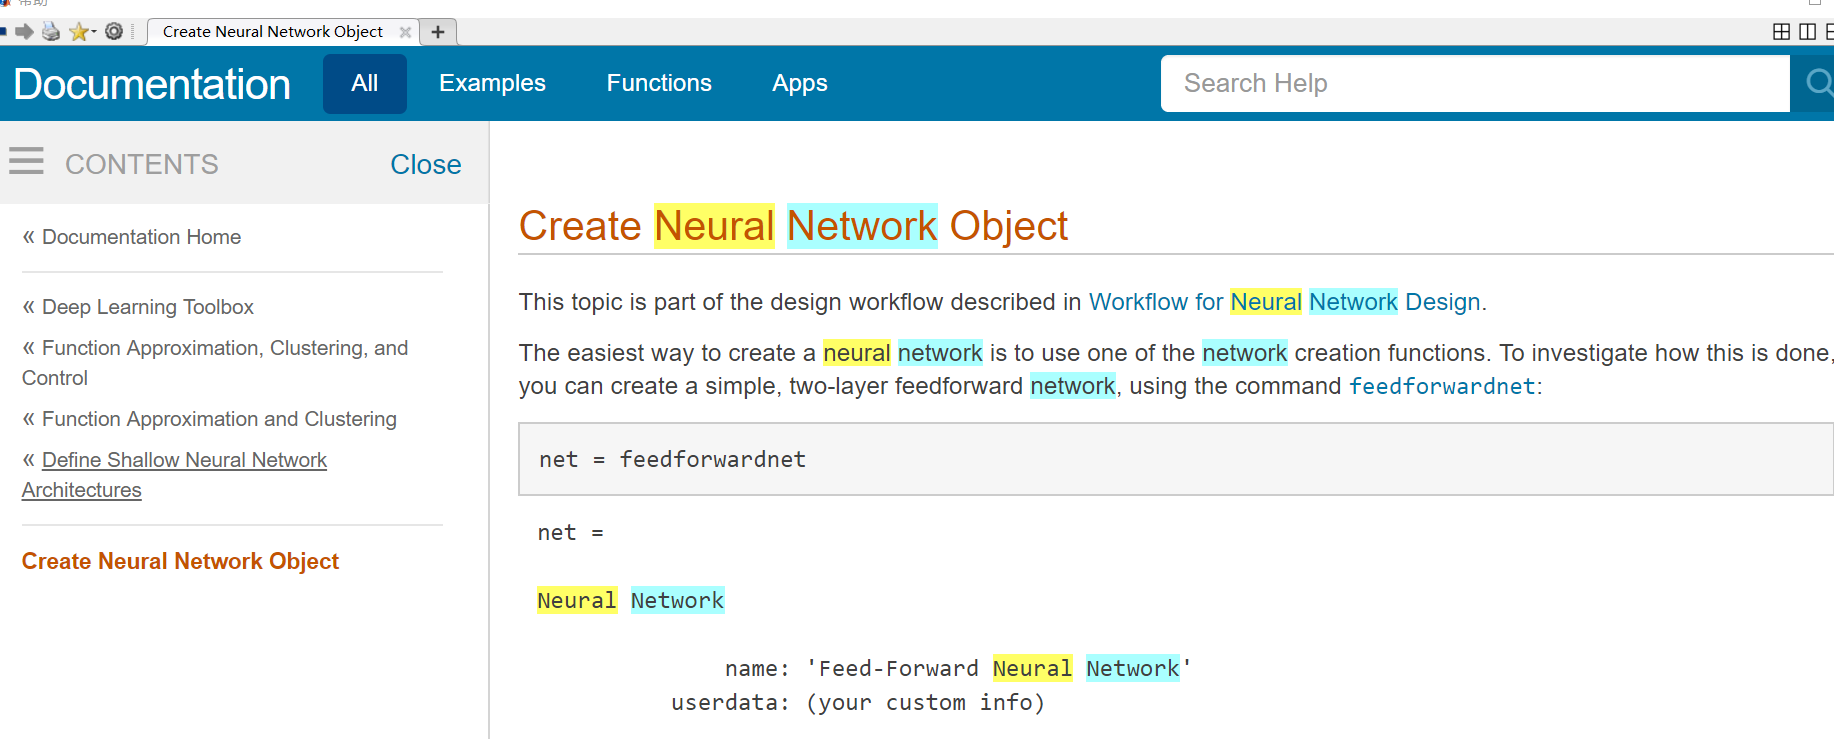

feedforwardnet(hiddenSize,trainFcn) 定义网络结构及网络的形式。

net = feedforwardnet

下面训练一个前向神经网络试试：

[x,t] = simplefit_dataset;
net = feedforwardnet(10);
net = train(net,x,t);
view(net)
y = net(x);
perf = perform(net,y,t)

[net,cr] = train(net,x,t,xi,ai,EW);

xi为初始输入延迟条件，默认为0，ai为初始层延迟条件，默认为0，EW为权重偏差，tr表示训练过程的记录值。

下面根据输入和目标值训练一个神经网络

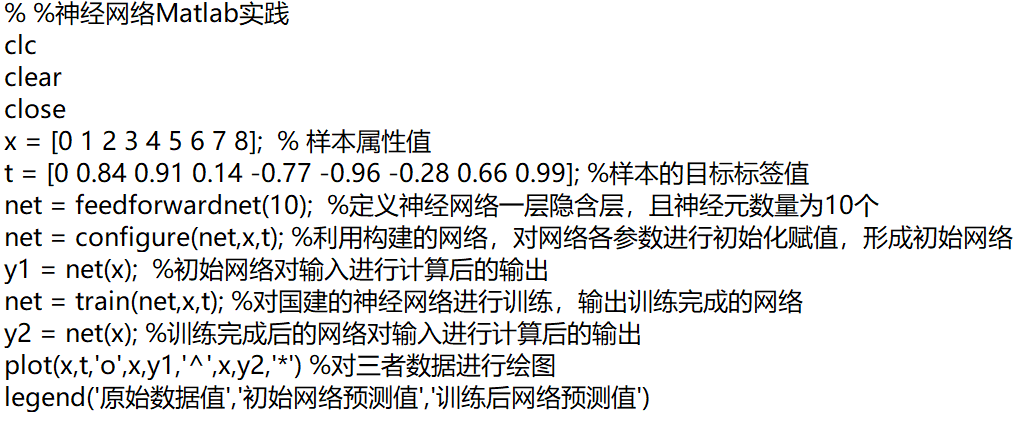

练习：

[https://www.cnblogs.com/dingdangsunny/p/12327324.html](https://www.cnblogs.com/dingdangsunny/p/12327324.html)

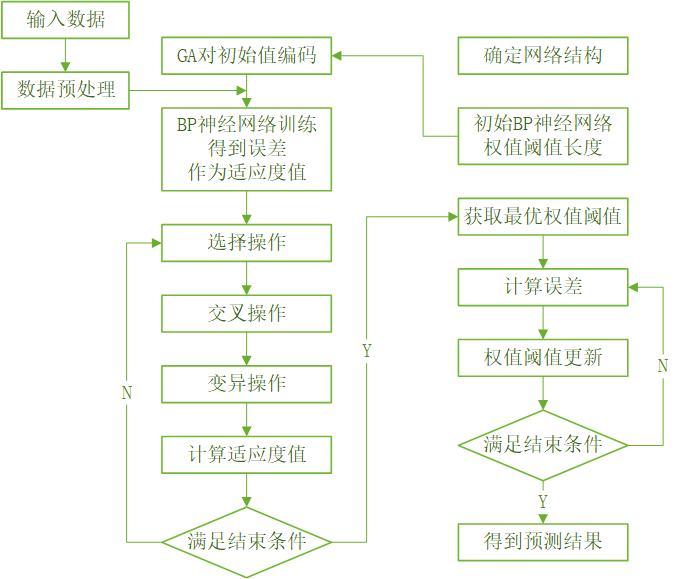

参考文献

- [意]朱塞佩.恰布罗，张雅仁等译，人民邮电出版社，matlab机器学习，2020年5月